# The WIM method for CICE6.

As CICE6 does not include wave propagation through ice, for wave forcing, we must attach a *waves-in-ice module* (WIM). This particular WIM has the following method:

- Take the signfiicant wave height, peak period and mean wave direction for the most northern ice-free cell.

- Apply a directional filter such that waves only propagate along longitudinal lines.

- Define the wave spectrum using a Bretschneider spectrum at this ice-free cell.

- Propagate through the ice (towards Antarctica) using the attenuation coefficent from Meylan et al. (2014).

- Calculate the signfiicant wave height and peak period for the propagated waves and feed this into CICE6.

% Preamble
clc
clear all
close all
addpath functions
%cd .. % Move up one directory
day = 9;
month = 1;
year = 2005;
sector = "SA";
if day < 9
    date = sprintf('%d-0%d-0%d', year, month, day);
else
    date = sprintf('%d-0%d-%d', year, month, day);
end
case_name = '31freq';
ticker = 1;
SIC = 0.15; 
filename = "/Volumes/NoahDay5TB/cases/31freq/history/iceh.2008-07-30.nc";%/Volumes/NoahDay5TB/cases/forcingnowaves/history/iceh.2005-07.nc";%"prra_input4MIPs_atmosphericState_OMIP_MRI-JRA55-do-1-5-0_gr_196201010130-196212312230.nc";
filename = "/Users/noahday/Maths1/access-forcing-2010-fixed-ic/history/2019/iceh.2019-09-01.nc";
filename = "/Volumes/NoahDay5TB/WIMonAlessandroRun/history/iceh.2017-09-01.nc";
%strcat('cases/',case_name,"/history/iceh.",date,".nc");
% '/Users/noahday/Gadi/2010/JRA55_03hr_forcing_2010.nc';%'grid/gridded_ww3.glob_24m.200501.nc'; 
%filename = 'DATA/CESM/MONTHLY/ocean_forcing_clim_2D_gx1.20210330.nc';
% Read the header
%ncdisp(filename)
sector = "SH";
grid = 'om2';
[lat,lon] = grid_read(grid);

%% Finding the ice edge
aice_data = data_format_sector(filename,"aice",sector);

[lat_ice_edge, lon_ice_edge,edge] = find_ice_edge(aice_data,SIC,sector,lat,lon);


% Plot areal ice concentration
 
conFigure(11,1)
f = figure;
[p,a] = map_plot(aice_data,"aice","SH",'om2');

plotm(lat_ice_edge,lon_ice_edge,'-','color',0.7*[0.4660 0.6740 0.1880],'LineWidth',2) % Dark green
t = textm(lat_ice_edge(20)-5,lon_ice_edge(300),sprintf('SIC = %g\n ice edge',SIC),'HorizontalAlignment','right');
t.Color = 0.7*[0.4660 0.6740 0.1880];
%s = scaleruler
% setm(handlem('scaleruler'), ...
%     'XLoc',0.3, ... '
%     'YLoc',-0.52, ...
%     'TickDir','down', ...
%     'MajorTick',0:1000:1000, ...
%     'MinorTick',0:500:500, ...
%     'MajorTickLength',km2nm(150),...
%     'MinorTickLength',km2nm(150))

a.Label.String = "Ice concentration";
a.Label.Interpreter = "latex";
cmocean('ice',10)

%exportgraphics(f,'aice.pdf','ContentType','vector')


% Take the wave data from CAWCR for these cells
filename = "/Users/noahday/GitHub/cice-dirs/input/CICE_data/forcing/access-om2_1deg/CAWCR/MONTHLY/2017/ww3_om2_1deg_201707.nc";
cawcr_filename = filename;
row = 37;
%ncdisp(filename)
lat = ncread(filename,"LAT");
lon = ncread(filename,"LON");
lat = rearrange_matrix(lat,row,2);
lon = rearrange_matrix(lon,row,2);
[m, ~] = size(lon);
lon = double([lon; lon(end,:) + 360/m]);
lat = double([lat; lat(end,:)]);
hour = 1;

dirdata = ncread(cawcr_filename,'dir');
dirdata = rearrange_matrix(dirdata,row,3);
cawcr_hr = dirdata(:,:,hour);
% fixing data
[m, ~] = size(lon);
dir_out = [cawcr_hr; cawcr_hr(end,:)];
mwd_data = dir_out(:,:,1);

dirdata = ncread(cawcr_filename,'fp');
dirdata = rearrange_matrix(dirdata,row,3);
cawcr_hr = dirdata(:,:,hour);
% fixing data
[m, ~] = size(lon);
dir_out = [cawcr_hr; cawcr_hr(end,:)];
fp_data = dir_out(:,:,1);

dirdata = ncread(cawcr_filename,'hs');
dirdata = rearrange_matrix(dirdata,row,3);
cawcr_hr = dirdata(:,:,hour);
% fixing data
[m, ~] = size(lon);
dir_out = [cawcr_hr; cawcr_hr(end,:)];
hs_data = dir_out(:,:,1);


% Plot the wave stats

% Wave direction
mwd_vec = reshape(mwd_data,1,[]);
x_vec = reshape(cos(mwd_data),1,[]);
y_vec = reshape(sin(mwd_data),1,[]);
lat_vec = reshape(lat,1,[]);
lon_vec = reshape(lon,1,[]);
scale = 0.5;
pram.quiver_color = 'red';
% Signficant wave height
conFigure(11,1)
f = figure;
w = worldmap('world');
    axesm eqaazim; %, eqaazim wetch eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-55]);
    setm(w, 'maplonlimit', [-180,-55]);

    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', 60);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'mlinelimit', [-75 -55]);
    setm(w, 'plinelimit', [-75 -55]);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'off');
    setm(w, 'labelrotation', 'on')
    pcolorm(double(lat),double(lon),hs_data) 
    %quiverm(lat_vec,lon_vec,x_vec,y_vec,pram.quiver_color,scale)
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    a = colorbar;
    a.Label.String = "Significant wave height [m]";
    a.TickLabelInterpreter = 'latex';
    a.Label.Interpreter = 'latex';
     caxis([0,10])
    
 exportgraphics(f,'cawcr.pdf','ContentType','vector')

    
% Peak frequency
conFigure(11,1)
f = figure;
w = worldmap('world');
    axesm eqaazim; %, eqaazim wetch eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-55]);
    setm(w, 'maplonlimit', [-180,-55]);

    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', 60);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'mlinelimit', [-75 -55]);
    setm(w, 'plinelimit', [-75 -55]);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'off');
    setm(w, 'labelrotation', 'on')
    pcolorm(double(lat),double(lon),fp_data.^(-1))
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    a = colorbar;
    a.Label.String = "Peak period [s]";
    a.TickLabelInterpreter = 'latex';
    a.Label.Interpreter = 'latex';

    
    
    
    
% SWH along ice edge
swh_ice_edge = zeros(size(lat)).*NaN;
for i = 1:length(edge)
    swh_ice_edge(i,edge(i)) = hs_data(i,edge(i));
    latedge_vec(i) = lat(i,edge(i));
    lonedge_vec(i) = lon(i,edge(i));
    xedge_vec(i) = cos(mwd_data(i,edge(i)));
    yedge_vec(i) = sin(mwd_data(i,edge(i)));
end 

scale = 0.1;
conFigure(11,1)
f = figure;
w = worldmap('world');
    axesm eqaazim; %, eqaazim wetch eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-50]);
    setm(w, 'maplonlimit', [-180,180]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', 60);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'mlinelimit', [-75 -55]);
    setm(w, 'plinelimit', [-75 -55]);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'off');
    setm(w, 'labelrotation', 'on')
    pcolorm(double(lat),double(lon),swh_ice_edge) 
    quiverm(latedge_vec,lonedge_vec,xedge_vec,yedge_vec,pram.quiver_color,scale)
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    a = colorbar;
    a.Label.String = "Significant wave height [m]";
    a.TickLabelInterpreter = 'latex';
    a.Label.Interpreter = 'latex';
      caxis([0,10])
exportgraphics(f,'ice_edge.pdf','ContentType','vector')




% Directional filter
for i = 1:length(edge)
    if mwd_data(i,edge(i)) > pi/2 && mwd_data(i,edge(i)) < 3*pi/2
        xedgefilt_vec(i) = cos(pi);
        yedgefilt_vec(i) = sin(pi);
    else
        xedgefilt_vec(i) = 0;
        yedgefilt_vec(i) = 0;
    end
end
scale = 0.1;
conFigure(11,1)
f = figure;
w = worldmap('world');
    axesm eqaazim; %, eqaazim wetch eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-50]);
    setm(w, 'maplonlimit', [-180,-55]);

    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', 60);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'mlinelimit', [-75 -50]);
    setm(w, 'plinelimit', [-75 -50]);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'off');
    setm(w, 'labelrotation', 'on')
    pcolorm(double(lat),double(lon),swh_ice_edge) 
    quiverm(latedge_vec,lonedge_vec,xedgefilt_vec,yedgefilt_vec,pram.quiver_color,scale)
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    a = colorbar;
    a.Label.String = "Significant wave height [m]";
    a.TickLabelInterpreter = 'latex';
    a.Label.Interpreter = 'latex';
    caxis([0,10])
    
exportgraphics(f,'ice_edge2.pdf','ContentType','vector')

    
    
% CICE output
filename = "/Volumes/NoahDay5TB/WIMonAlessandroRun/history/iceh.2017-09-01.nc";

swh_data = data_format_sector(filename,"wave_sig_ht",sector);
ppd_data = data_format_sector(filename,"peak_period",sector);
mwd_data = data_format_sector(filename,"mean_wave_dir",sector);

idx = swh_data < eps;
swh_data(idx) = NaN;
conFigure(11,1)
f = figure;
w = worldmap('world');
    axesm eqaazim; %, eqaazim wetch eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-55]);
    setm(w, 'maplonlimit', [-180,-55]);

    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', 60);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'mlinelimit', [-75 -55]);
    setm(w, 'plinelimit', [-75 -55]);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'off');
    setm(w, 'labelrotation', 'on')
    pcolorm(double(lat),double(lon),swh_data) 
    %quiverm(latedge_vec,lonedge_vec,xedge_vec,yedge_vec,pram.quiver_color,scale)
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    a = colorbar;
    a.Label.String = "Significant wave height [m]";
    a.TickLabelInterpreter = 'latex';
    a.Label.Interpreter = 'latex';
 caxis([0,10])
        
 exportgraphics(f,'wave_prop_cice.pdf','ContentType','vector')

% Plot what the Bretschneider spectrum may look like





## 1D wave propagation (and attenuation)

Method

- Read in WW3 wave data (CAWCR)

- Initialise the wave spectrum using Bretschneider

- Apply directional spreading and filter for the waves with direction between -pi/2 and pi/2 (where south is located at 0).

- Apply scattering attenuation when the waves first encouter 10% sea ice concentration

- Apply the adjusted MBK attenuation

% Attenuate and propagate waves in 1D


% Read data in ----------------------------------------------------------------------------------------
addpath functions
filename_ww3 = '/Users/noahday/GitHub/cice-dirs/input/CICE_data/forcing/access-om2_1deg/CAWCR/MONTHLY/2017/ww3_om2_1deg_201707.nc';
filename = '/Volumes/NoahDay5TB/WIMonAlessandroRun/history/iceh.2017-07-01.nc';
sector = "SH";
grid = 'om2';
aicen_data = data_format_sector(filename,'aicen',sector);
aice_data = sum(aicen_data,3);

swh_data = data_format_cawcr(filename_ww3,'hs');
swh_data = swh_data(:,:,1);
fp_data = data_format_cawcr(filename_ww3,'fp');
fp_data = fp_data(:,:,1);
idx = fp_data < 0;
fp_data(idx) = NaN;
ppd_data = 1./fp_data;
mwd_data = data_format_cawcr(filename_ww3,'dir');
mwd_data = mwd_data(:,:,1);
hte_data = data_format_sector(filename,'HTE',sector);
hice_data = data_format_sector(filename,'hi',sector);
fsdrad_data = data_format_sector(filename,'fsdrad',sector);
[lat,lon] = grid_read(grid);


%lon_pos = 30;
clear Hs Hs_nospread Hs_scattering Hs_adj
Hs = zeros(size(lon));
Hs_nospread = zeros(size(lon));
Hs_scattering = zeros(size(lon));
Hs_adj = zeros(size(lon));

%lon_required = 90;
%cell_lon_idx = near1(lon(:,1),lon_required); % The cell with longitude closest to lon_required

% Parameters ----------------------------------------------------------------------------------------
    tolice = 1.0e-2;               % conc<tolice treated as zero ice
    tolh   = 1.0e-1;               % h<tolh      treated as zero ice
    toli   = 1.0e-16;              % threshold for the propagation of waves
    gravity = 9.80665;
    puny = 1.0e-11;       




lon_range = 1:360;
for lon_pos = lon_range
    lat_range = 1:60;
    swh_data_vec= swh_data(lon_pos,lat_range);
    aice_data_vec= aice_data(lon_pos,lat_range);
    hice_data_vec= hice_data(lon_pos,lat_range);
    lat_vec = lat(lon_pos,lat_range);
    

    
    cell_lon_idx = lon_pos;
    aice_gt_puny = find(aice_data_vec>eps);
    if isempty(aice_gt_puny)
        wave_lat = 3;
    else
        wave_lat =  aice_gt_puny(end)+1; % The last cell with aice > puny
    end
    length_transect = wave_lat - 1;
    
    Hs_init = swh_data(cell_lon_idx,wave_lat);
    Tp_init = ppd_data(cell_lon_idx,wave_lat);
    
    dir_spread = 1; % = 1, we are reading in CAWCR data
    
    % 1. Intialise wave spectrum at wave_lat
    nw = 31;
    clear S_attn S_attn_nospread int_D S_attn_scattering
    [S_init,omega,T] = SDF_Bretschneider(Hs_init,Tp_init,nw); 
    wavefreq = omega/(2*pi);
    dwavefreq = wavefreq(1:end) - [0,wavefreq(1:end-1)];
    mwd = mwd_data(cell_lon_idx, wave_lat)*(pi/180); % Mean wave direction, rad
    thn = 31; % number of theta bins
    n = 2.5; % Cosine exponent
    
    if dir_spread == 1
        [S_spread,D,theta_vec] = cosine_spreader(S_init,mwd,thn,n);
        dtheta = theta_vec(1:end) - [0,theta_vec(1:end-1)];
        S_attn(1,:) = S_spread;
        S_attn_nospread(1,:) = S_init;
        S_attn_scattering(1,:) = S_spread;
        S_attn_adj = S_spread;
    else
        S_attn(1,:) = S_init;
    end
    
    % 2. Propagate the waves, sub_uncoupled          
    % increment_floe
    %! !DESCRIPTION:
    %!
    %!  Increase ice floe tracer by scaled timestep length.
    
    L_data = hte_data(cell_lon_idx,wave_lat:-1:wave_lat-length_transect); % Length of cell, converting km to m
    
    
    dwavew = dwavefreq.*(2*pi);
    conc_vec = aice_data_vec(wave_lat-1:-1:1);
    scatter_pos = find(conc_vec > 0.1);
    if isempty(scatter_pos)
        scatter_loc = 0;
    else
        scatter_loc = scatter_pos(1);
        scatter_loc_vec(lon_pos) = scatter_loc;
    end
    
    prop_length = find(~isnan(aice_data_vec(wave_lat:-1:1)));
    if isempty(prop_length)
        prop_length = 1;
    else
        prop_length = prop_length(end);% Propagation length, cells
        prop_length = wave_lat - 2;
    end

    for i = 1:prop_length
        conc = aice_data_vec(wave_lat-i);
        hice = hice_data_vec(wave_lat-i);
        floe_size = fsdrad_data(cell_lon_idx,wave_lat-i-1);% Radius, m
        Lcell = L_data(wave_lat-i-1); % initialise propagation length
    
        if conc < tolice 
            % As there is no ice, apply no attenuation
            S_attn(i+1,:) = S_attn(i,:);
            S_attn_nospread(i+1,:) = S_attn_nospread(i,:);
            S_attn_scattering(i+1,:) = S_attn_scattering(i,:);
            S_attn_adj(i+1,:) = S_attn_adj(i,:);
        elseif conc > tolice % Attenuate
            S_attn(i+1,:) = wave_attenuation(conc,Lcell,nw,S_attn(i,:),omega,"MBK",floe_size);
            S_attn_nospread(i+1,:) = wave_attenuation(conc,Lcell,nw,S_attn_nospread(i,:),omega,"MBK",floe_size); 
            if i == scatter_loc
               [S_attn_scattering(i,:) ] = wave_scatter(S_attn_scattering(i,:),omega,floe_size);
                S_attn_scattering(i+1,:) = wave_attenuation(conc,Lcell,nw,S_attn_scattering(i,:),omega,"MBK",floe_size);
               [S_attn_adj(i,:) ] = wave_scatter(S_attn_adj(i,:),omega,floe_size);
                S_attn_adj(i+1,:) = wave_attenuation(conc,Lcell,nw,S_attn_adj(i,:),omega,"adjusted",floe_size);  
            else
                S_attn_scattering(i+1,:) = wave_attenuation(conc,Lcell,nw,S_attn_scattering(i,:),omega,"MBK",floe_size);
                S_attn_adj(i+1,:) = wave_attenuation(conc,Lcell,nw,S_attn_adj(i,:),omega,"adjusted",floe_size);
            end
        elseif isnan(conc)
            S_attn(i+1,:) = NaN;
            S_attn_nospread(i+1,:) = NaN;
            S_attn_scattering(i+1,:) = NaN;
            S_attn_adj(i+1,:) = NaN;
        end
    
        Hs_scattering(cell_lon_idx,wave_lat-i-1) = 4*sqrt(sum(S_attn_scattering(i,:).*dwavew));
        Hs(cell_lon_idx,wave_lat-i-1) = 4*sqrt(sum(S_attn(i,:).*dwavew));
        Hs_nospread(cell_lon_idx,wave_lat-i-1) = 4*sqrt(sum(S_attn_nospread(i,:).*dwavew));
        Hs_adj(cell_lon_idx,wave_lat-i-1) = 4*sqrt(sum(S_attn_adj(i,:).*dwavew));

        % Calculate the wave height for each wave type
        lambda = gravity./(2*pi*(wavefreq).^2); % Wavelength, m
        idx_wind = lambda < 50;
        idx_swell = lambda > 50 & lambda < 154; % 154 instead of 150 as one point is at 153
        idx_long = lambda > 154;
        Hs_wind(cell_lon_idx,wave_lat-i-1) = 4*sqrt(sum(S_attn_adj(i,idx_wind).*dwavew(idx_wind)));
        Hs_swell(cell_lon_idx,wave_lat-i-1) = 4*sqrt(sum(S_attn_adj(i,idx_swell).*dwavew(idx_swell)));
        Hs_long(cell_lon_idx,wave_lat-i-1) = 4*sqrt(sum(S_attn_adj(i,idx_long).*dwavew(idx_long)));
    end % i, prop_length
end


% 
% cell_lon_idx = 80;
% land_pos = find(isnan(aice_data(cell_lon_idx,1:wave_lat)));
% 
 land_mask = isnan(aice_data(cell_lon_idx,:));
 Hs_nospread(cell_lon_idx,land_mask) = NaN;
 Hs(cell_lon_idx,land_mask) = NaN;
 Hs_scattering(cell_lon_idx,land_mask) = NaN;
 Hs_adj(cell_lon_idx,land_mask) = NaN;
 
 Hs_nospread(Hs_nospread==0) = NaN;
 Hs(Hs==0) = NaN;
 Hs_scattering(Hs_scattering==0) = NaN;
 Hs_adj(Hs_adj==0) = NaN;

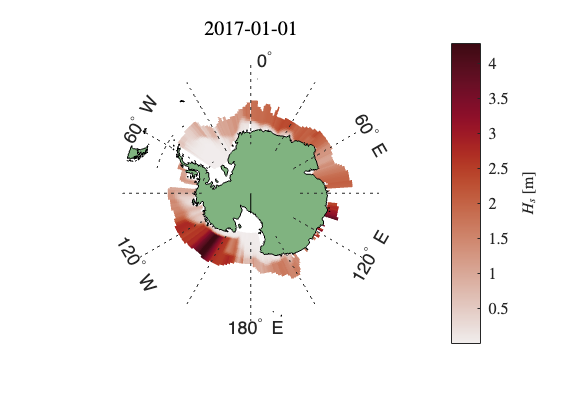

% World map
%idx = isnan(Hs);
%Hs(idx) = 0;
%idx = isnan(Hs_scattering);
%Hs_scattering(idx) = 0;
conFigure(11)
f = figure;
w = worldmap('world');
    axesm eqaazim; %, eqaazim wetch eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-50]);
    setm(w, 'maplonlimit', [-180,180]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', 60);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'mlinelimit', [-75 -50]);
    setm(w, 'plinelimit', [-75 -50]);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'off');
    setm(w, 'labelrotation', 'on')
    pcolorm(lat,lon,Hs_adj) 
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    a = colorbar;
    a.Label.String = "$H_s$ [m]";
    a.TickLabelInterpreter = 'latex';
    a.Label.Interpreter = 'latex';
    title(filename(end-12:end-3))
    %caxis([0,9])
    %colormap(cmocean('balance','pivot'))
    colormap(cmocean('amp'))
exportgraphics(f,strcat('HsAdjusted',filename(end-12:end-3),'.pdf'),'ContentType','vector')

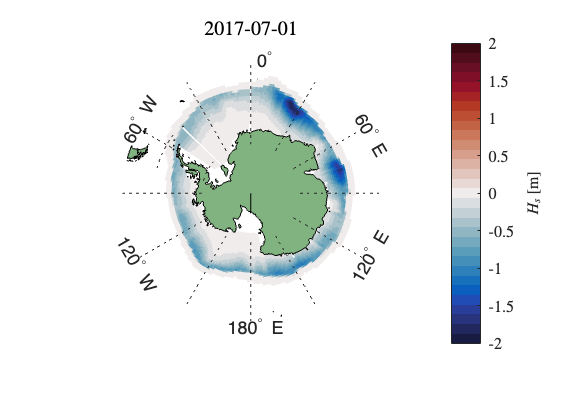

conFigure(11)
f = figure;
w = worldmap('world');
    axesm eqaazim; %, eqaazim wetch eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-50]);
    setm(w, 'maplonlimit', [-180,180]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', 60);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'mlinelimit', [-75 -50]);
    setm(w, 'plinelimit', [-75 -50]);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'off');
    setm(w, 'labelrotation', 'on')
    pcolorm(lat,lon,Hs_adj-Hs_scattering) 
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    a = colorbar;
    a.Label.String = "$H_s$ [m]";
    a.TickLabelInterpreter = 'latex';
    a.Label.Interpreter = 'latex';
    caxis([-2,2])
    cmap_cols = cmocean('balance','pivot',0,31);%-10^(-3));
    %cmap_cols = cmap_cols.^2;
    %cmap_temp = cmocean('balance',10,'pivot',0);
    %cmap_cols(end,:) = [0.9,0.9,.9];
    set(gca,'ColorScale','linear')
    colormap(cmap_cols)
    title(filename(end-12:end-3))
    %colormap(cmocean('amp'))
exportgraphics(f,strcat('HsCompAdj-Scatter',filename(end-12:end-3),'.pdf'),'ContentType','vector')

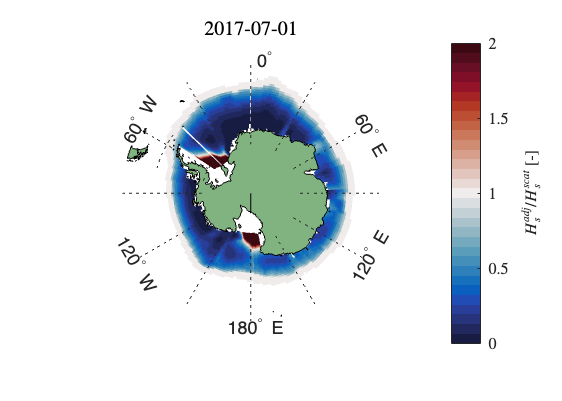


conFigure(11)
f = figure;
w = worldmap('world');
    axesm eqaazim; %, eqaazim wetch eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-50]);
    setm(w, 'maplonlimit', [-180,180]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', 60);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'mlinelimit', [-75 -50]);
    setm(w, 'plinelimit', [-75 -50]);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'off');
    setm(w, 'labelrotation', 'on')
    pcolorm(lat,lon,Hs_adj./Hs_scattering) 
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    a = colorbar;
    a.Label.String = "$H_s^{adj}/H_s^{scat}$ [-]";
    a.TickLabelInterpreter = 'latex';
    a.Label.Interpreter = 'latex';
    caxis([0,2])
    cmap_cols = cmocean('balance','pivot',1,31);%-10^(-3));
    %cmap_cols = cmap_cols.^2;
    %cmap_temp = cmocean('balance',10,'pivot',0);
    %cmap_cols(end,:) = [0.9,0.9,.9];
    set(gca,'ColorScale','linear')
    colormap(cmap_cols)
    title(filename(end-12:end-3))
    %colormap(cmocean('amp'))
exportgraphics(f,strcat('HsRelativeAdj-Scatter',filename(end-12:end-3),'.pdf'),'ContentType','vector')

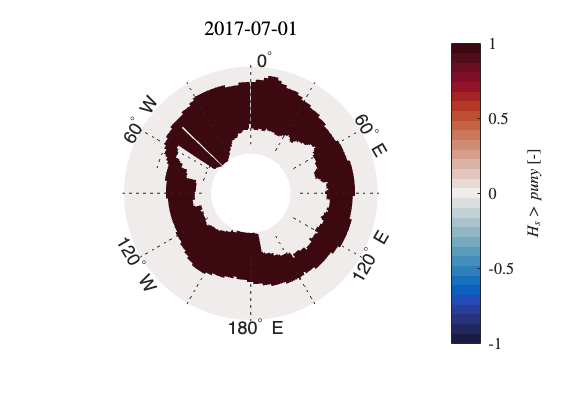


puny = 1e-11;

conFigure(11)
f = figure;
w = worldmap('world');
    axesm eqaazim; %, eqaazim wetch eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-50]);
    setm(w, 'maplonlimit', [-180,180]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', 60);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'mlinelimit', [-75 -50]);
    setm(w, 'plinelimit', [-75 -50]);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'off');
    setm(w, 'labelrotation', 'on')
    pcolorm(lat,lon,double(Hs_adj>puny))
    %land = shaperead('landareas', 'UseGeoCoords', true);
    %geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    a = colorbar;
    a.Label.String = "$H_s > puny$ [-]";
    a.TickLabelInterpreter = 'latex';
    a.Label.Interpreter = 'latex';
    caxis([-1,1])
    cmap_cols = cmocean('balance','pivot',0,31);%-10^(-3));
    %cmap_cols = cmap_cols.^2;
    %cmap_temp = cmocean('balance',10,'pivot',0);
    %cmap_cols(end,:) = [0.9,0.9,.9];
    set(gca,'ColorScale','linear')
    colormap(cmap_cols)
    title(filename(end-12:end-3))
    %colormap(cmocean('amp'))
exportgraphics(f,strcat('Hs_gt_puny',filename(end-12:end-3),'.pdf'),'ContentType','vector')

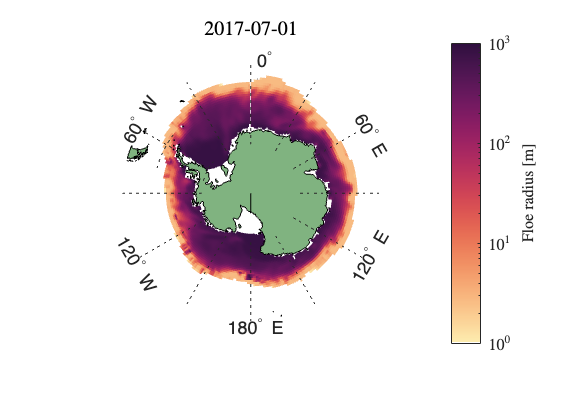


fsdrad_data_map = fsdrad_data;
idx = aice_data < 0.1;
fsdrad_data_map(idx) = NaN;

conFigure(11)
f = figure;
w = worldmap('world');
    axesm eqaazim; %, eqaazim wetch eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-50]);
    setm(w, 'maplonlimit', [-180,180]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', 60);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'mlinelimit', [-75 -50]);
    setm(w, 'plinelimit', [-75 -50]);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'off');
    setm(w, 'labelrotation', 'on')
    pcolorm(lat,lon,fsdrad_data) 
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    a = colorbar;
    a.Label.String = "Floe radius [m]";
    a.TickLabelInterpreter = 'latex';
    a.Label.Interpreter = 'latex';
    caxis([1,1000])
    cmap_cols = cmocean('matter');
    cmap_cols(1,:) = [1,1,1];
    set(gca,'ColorScale','log')
    colormap(cmap_cols)
    title(filename(end-12:end-3))
    %colormap(cmocean('amp'))
exportgraphics(f,strcat('fsdradmap',filename(end-12:end-3),'.pdf'),'ContentType','vector')

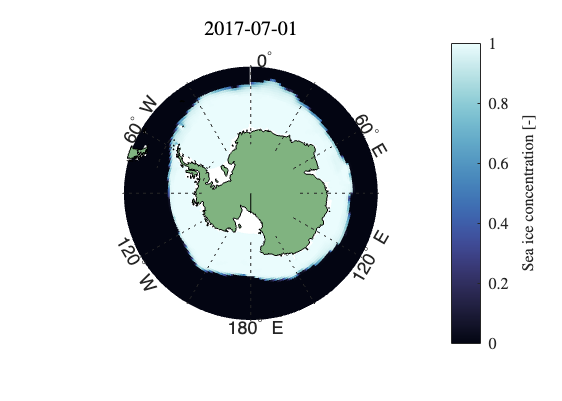



conFigure(11)
f = figure;
w = worldmap('world');
    axesm eqaazim; %, eqaazim wetch eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-50]);
    setm(w, 'maplonlimit', [-180,180]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', 60);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'mlinelimit', [-75 -50]);
    setm(w, 'plinelimit', [-75 -50]);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'off');
    setm(w, 'labelrotation', 'on')
    pcolorm(lat,lon,aice_data) 
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    a = colorbar;
    a.Label.String = "Sea ice concentration [-]";
    a.TickLabelInterpreter = 'latex';
    a.Label.Interpreter = 'latex';
    caxis([0,1])
    cmocean('ice')
    set(gca,'ColorScale','linear')
    title(filename(end-12:end-3))
exportgraphics(f,strcat('aicemap',filename(end-12:end-3),'.pdf'),'ContentType','vector')

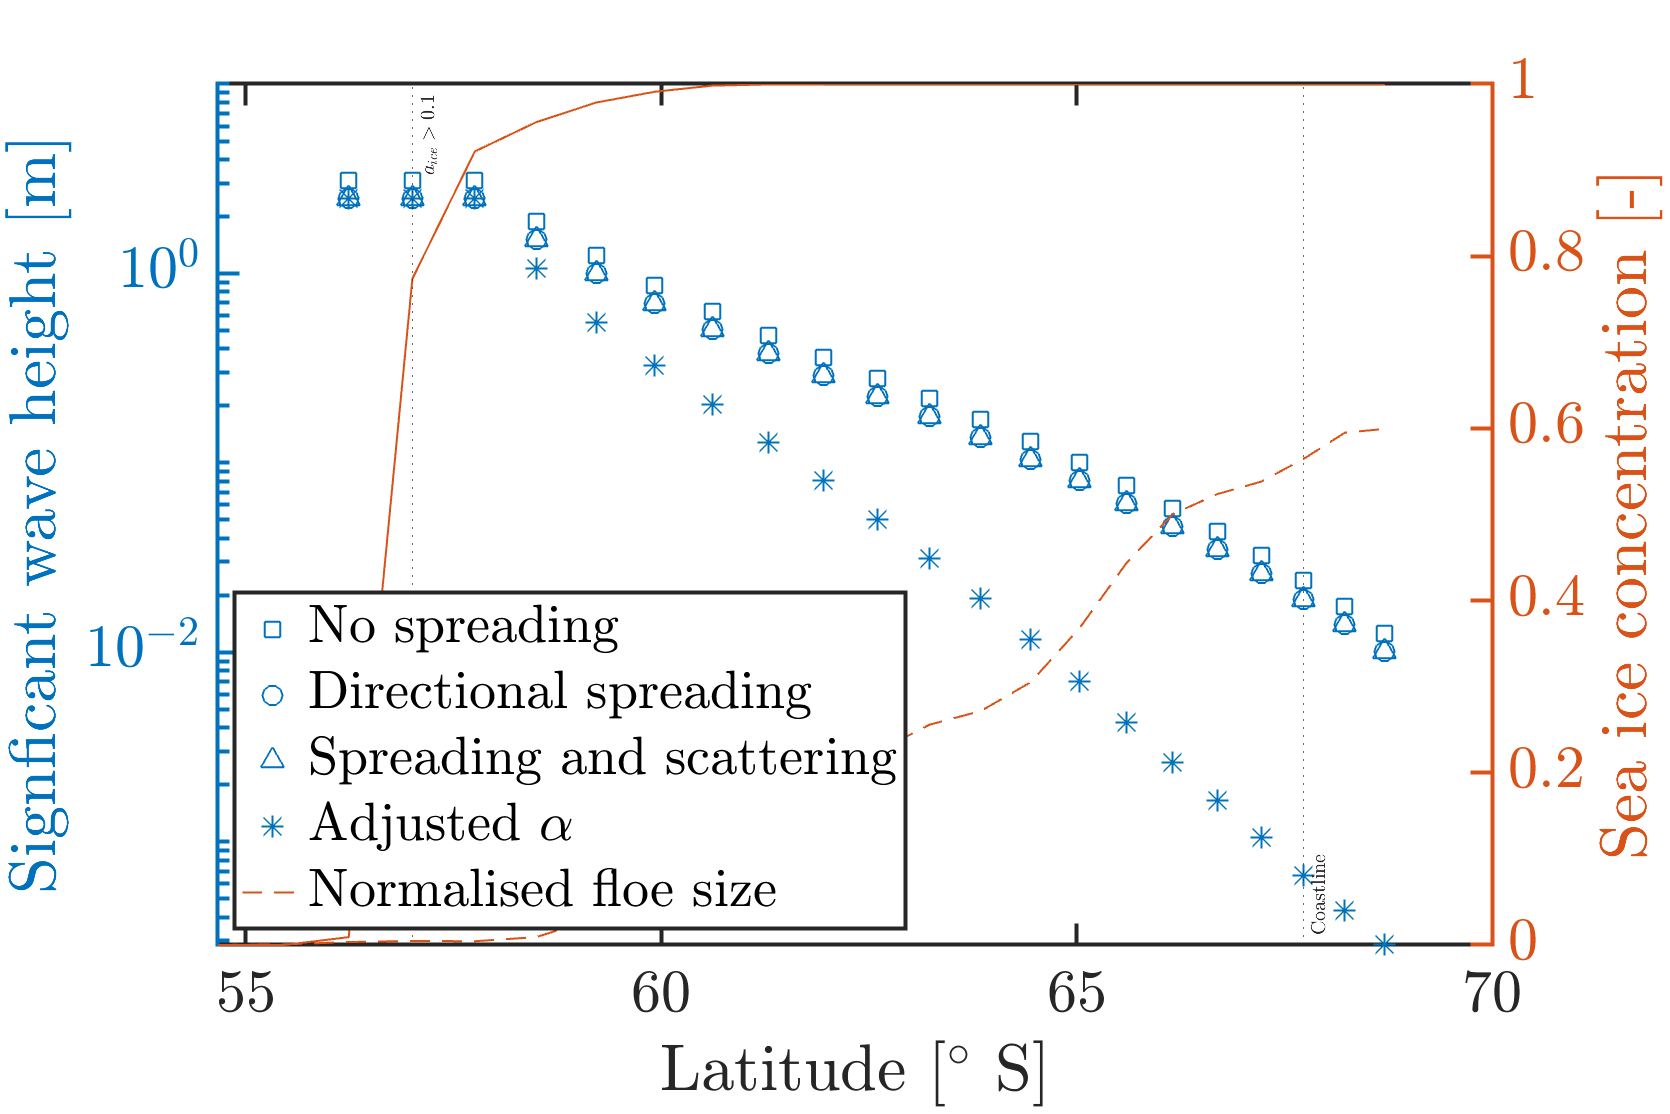

marker_size = 10;
conFigure(30,1.5)
f = figure;
yyaxis left
plot(-lat(cell_lon_idx,1:wave_lat),Hs_nospread(cell_lon_idx,1:wave_lat),'s','MarkerSize',marker_size)
hold on
plot(-lat(cell_lon_idx,1:wave_lat),Hs(cell_lon_idx,1:wave_lat),'o','MarkerSize',marker_size)
plot(-lat(cell_lon_idx,1:wave_lat),Hs_scattering(cell_lon_idx,1:wave_lat),'^','MarkerSize',marker_size)
plot(-lat(cell_lon_idx,1:wave_lat),Hs_adj(cell_lon_idx,1:wave_lat),'*','MarkerSize',marker_size)
set(gca,'Yscale','log')
xa = [0.3,0.3]; %[-lat(cell_lon_idx,lat_range(end)-1) -lat(cell_lon_idx,lat_range(end)-1)];
ya = [0.55,0.68]; %[Hs(3) Hs_nospread(3)];
%annotation('doublearrow',xa,ya,'Linewidth',1,'Head1Width',5,'Head2Width',5,'Head1Length',3,'Head2Length',3)
%text(-lat(cell_lon_idx,lat_range(end)+3)-0.25,(Hs(end-2) + Hs_nospread(end-2))/2+0.5,'Directional')
%text(-lat(cell_lon_idx,lat_range(end)+3)-0.25,(Hs(end-2) + Hs_nospread(end-2))/2-0.1,'spread')
%xlim([-80,-50])
ylim([0,10])
ylabel('Signficant wave height [m]')
%hold on
%plot(-lat(cell_lon_idx,wave_lat:-1:wave_lat-length_transect+1),swh_data(cell_lon_idx,wave_lat:-1:wave_lat-length_transect+1))
yyaxis right
plot(-lat(cell_lon_idx,wave_lat:-1:wave_lat-length_transect+1),fsdrad_data(cell_lon_idx,wave_lat:-1:wave_lat-length_transect+1)./850,'--')
plot(-lat(cell_lon_idx,wave_lat:-1:1),aice_data(cell_lon_idx,wave_lat:-1:1),'-','LineWidth',1)
pos = find(aice_data(cell_lon_idx,:) > 0.1);
xline(-lat(cell_lon_idx,pos(end)),':',{'$a_{ice} > 0.1$'},'Interpreter','latex')
xline(-lat(cell_lon_idx,land_pos(end)+1),':',{'Coastline'},'Interpreter','latex','LabelVerticalAlignment','bottom')

%pos = find(aice_data(cell_lon_idx,:) > 0.01);
%xline(-lat(cell_lon_idx,pos(end)),'--',{'$a_{ice} > 0.01$'},'Interpreter','latex')
ylabel('Sea ice concentration [-]')
%ylabel('Representative floe radius [m]')
hold off
xlabel('Latitude [$^\circ$ S]')
%title(sprintf('$H_s =$ %g m, $T_p =$ %g s, $\theta_m$ = %g rad., $r_a$ = %g m',round(Hs_init,2), round(Tp_init,2), round(mwd,2), round(floe_size,2)),'Interpreter','latex')
legend('No spreading','Directional spreading','Spreading and scattering','Adjusted $\alpha$','Normalised floe size','','Location','southwest','orientation','vertical')
exportgraphics(f,'1dprop.pdf','ContentType','vector')

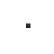

figure
plot(lambda)
set(gca,'Yscale','log')

## Transect analysis of different wave heights

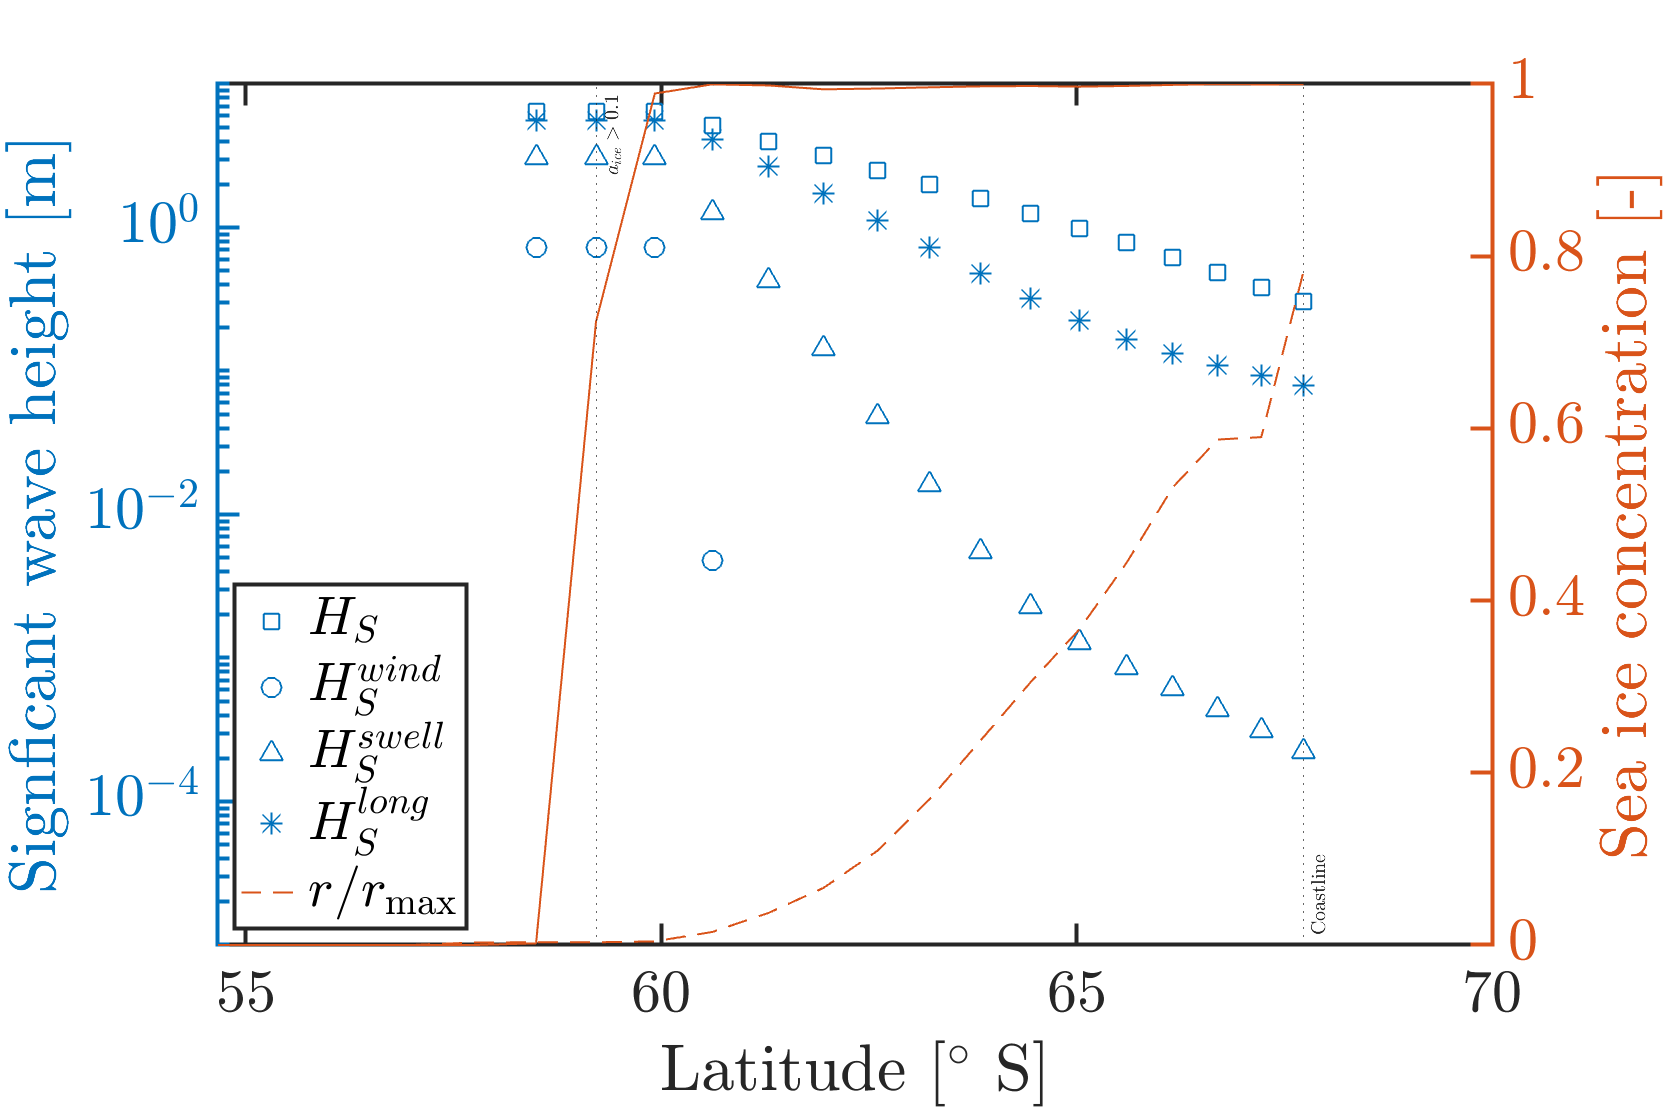

% Prep
cell_lon_idx = 80;
land_pos = find(isnan(aice_data(cell_lon_idx,1:wave_lat)));

land_mask = isnan(aice_data(cell_lon_idx,:));
Hs_wind(cell_lon_idx,land_mask) = NaN;
Hs(cell_lon_idx,land_mask) = NaN;
Hs_swell(cell_lon_idx,land_mask) = NaN;
Hs_long(cell_lon_idx,land_mask) = NaN;

Hs_wind(Hs_wind==0) = NaN;
Hs(Hs==0) = NaN;
Hs_swell(Hs_swell==0) = NaN;
Hs_long(Hs_long==0) = NaN;



marker_size = 10;
conFigure(30,1.5)
f = figure;
yyaxis left
plot(-lat(cell_lon_idx,1:wave_lat),Hs(cell_lon_idx,1:wave_lat),'s','MarkerSize',marker_size)
hold on
plot(-lat(cell_lon_idx,1:wave_lat),Hs_wind(cell_lon_idx,1:wave_lat),'o','MarkerSize',marker_size)
plot(-lat(cell_lon_idx,1:wave_lat),Hs_swell(cell_lon_idx,1:wave_lat),'^','MarkerSize',marker_size)
plot(-lat(cell_lon_idx,1:wave_lat),Hs_long(cell_lon_idx,1:wave_lat),'*','MarkerSize',marker_size)
set(gca,'Yscale','log')

ylim([10^(-5),10])
ylabel('Signficant wave height [m]')
yyaxis right
plot(-lat(cell_lon_idx,wave_lat:-1:wave_lat-length_transect+1),fsdrad_data(cell_lon_idx,wave_lat:-1:wave_lat-length_transect+1)./850,'--')
plot(-lat(cell_lon_idx,wave_lat:-1:1),aice_data(cell_lon_idx,wave_lat:-1:1),'-','LineWidth',1)
pos = find(aice_data(cell_lon_idx,:) > 0.1);
xline(-lat(cell_lon_idx,pos(end)),':',{'$a_{ice} > 0.1$'},'Interpreter','latex')
xline(-lat(cell_lon_idx,land_pos(end)+1),':',{'Coastline'},'Interpreter','latex','LabelVerticalAlignment','bottom')

ylabel('Sea ice concentration [-]')
hold off
xlabel('Latitude [$^\circ$ S]')
legend('$H_S$','$H_S^{wind}$','$H_S^{swell}$','$H_S^{long}$','$r/r_{\max}$','','Location','southwest','orientation','vertical')
exportgraphics(f,'wavetype_transect.pdf','ContentType','vector')

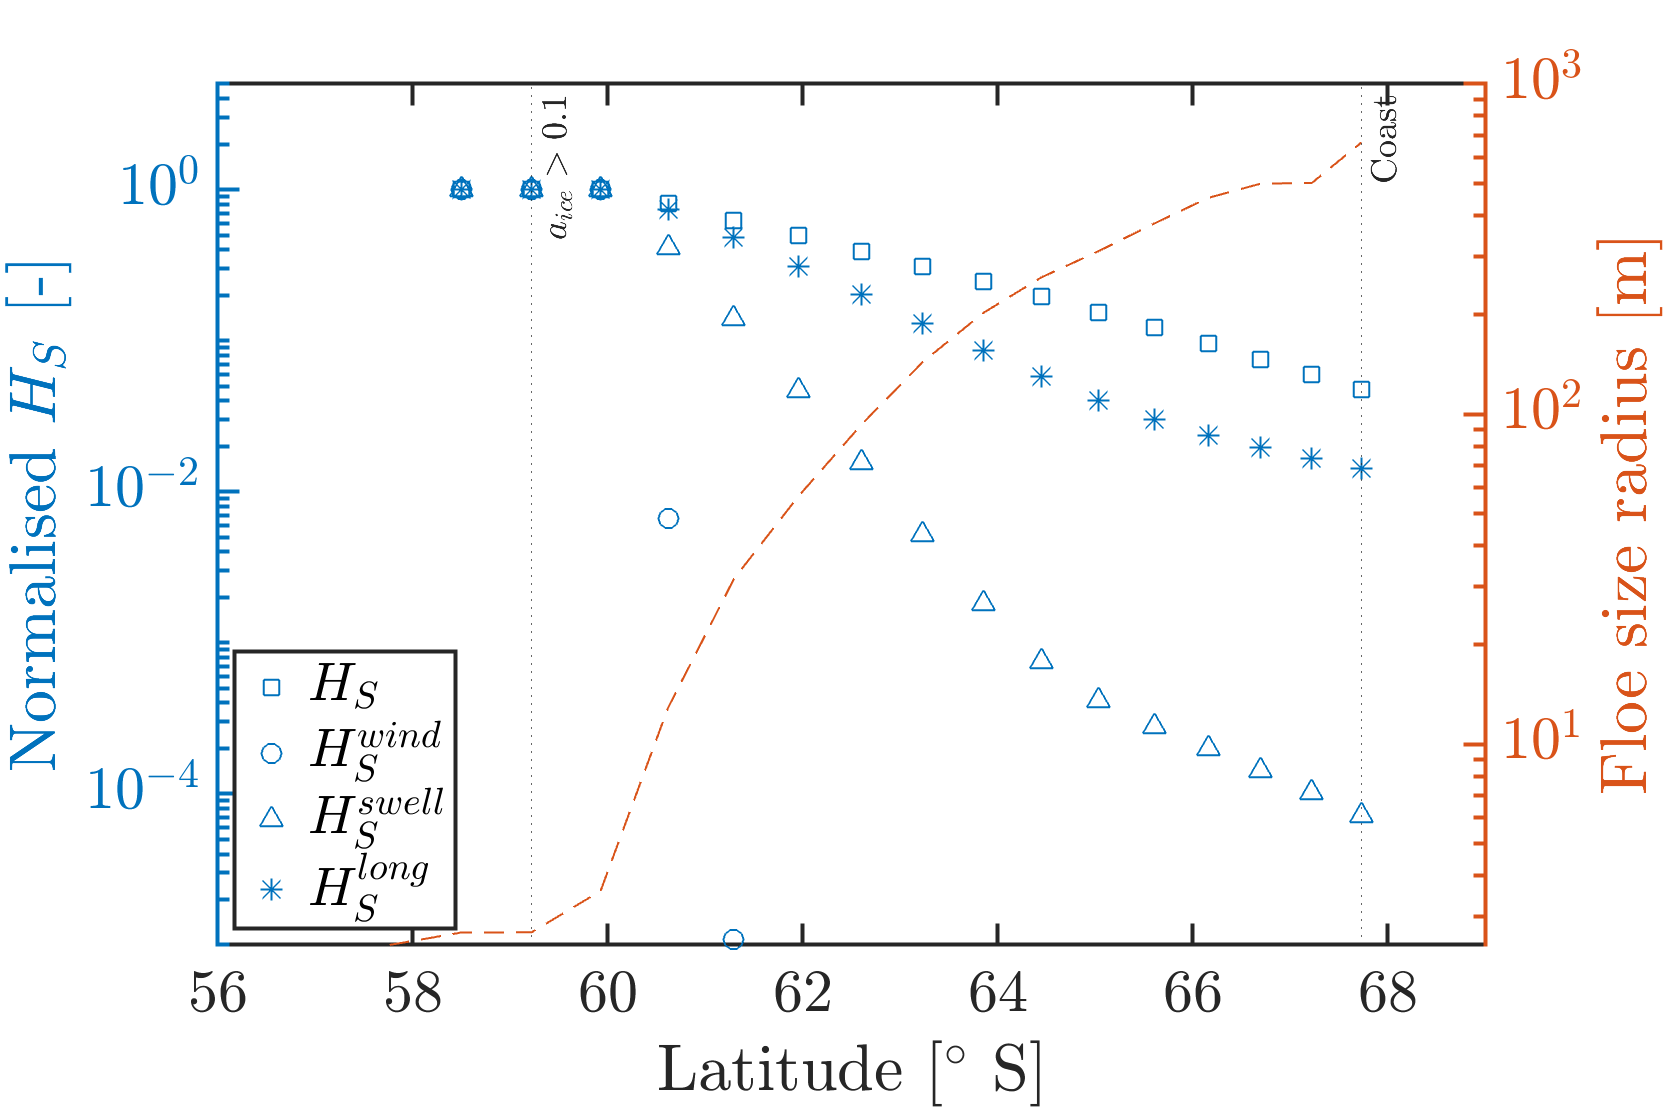



marker_size = 10;
conFigure(30,1.5)
f = figure;
yyaxis left
plot(-lat(cell_lon_idx,1:wave_lat),Hs(cell_lon_idx,1:wave_lat)./max(Hs(cell_lon_idx,1:wave_lat)),'s','MarkerSize',marker_size)
hold on
plot(-lat(cell_lon_idx,1:wave_lat),Hs_wind(cell_lon_idx,1:wave_lat)./max(Hs_wind(cell_lon_idx,1:wave_lat)),'o','MarkerSize',marker_size)
plot(-lat(cell_lon_idx,1:wave_lat),Hs_swell(cell_lon_idx,1:wave_lat)./max(Hs_swell(cell_lon_idx,1:wave_lat)),'^','MarkerSize',marker_size)
plot(-lat(cell_lon_idx,1:wave_lat),Hs_long(cell_lon_idx,1:wave_lat)./max(Hs_long(cell_lon_idx,1:wave_lat)),'*','MarkerSize',marker_size)
set(gca,'Yscale','log')

ylim([10^(-5),5])
ylabel('Normalised $H_S$ [-]')
yyaxis right
plot(-lat(cell_lon_idx,wave_lat:-1:wave_lat-length_transect+1),fsdrad_data(cell_lon_idx,wave_lat:-1:wave_lat-length_transect+1),'--')
%plot(-lat(cell_lon_idx,wave_lat:-1:1),aice_data(cell_lon_idx,wave_lat:-1:1),'-','LineWidth',1)
pos = find(aice_data(cell_lon_idx,:) > 0.1);
font_size = 18;
xline(-lat(cell_lon_idx,pos(end)),':',{'$a_{ice} > 0.1$'},'Interpreter','latex','fontsize',font_size)
xline(-lat(cell_lon_idx,land_pos(end)+1),':',{'Coast'},'Interpreter','latex','LabelVerticalAlignment','top','fontsize',font_size)
%pos = find(fsdrad_data(cell_lon_idx,1:wave_lat)>25);
%xline(-lat(cell_lon_idx,pos(end)),':',{'$d > 50$'},'Interpreter','latex')
%pos = find(fsdrad_data(cell_lon_idx,1:wave_lat)>75);
%xline(-lat(cell_lon_idx,pos(end)),':',{'$d > 75$'},'Interpreter','latex')

%pos = find(fsdrad_data(cell_lon_idx,1:wave_lat)>125);
%xline(-lat(cell_lon_idx,pos(end)),':',{'$d > 5\times 50$'},'Interpreter','latex')
%pos = find(fsdrad_data(cell_lon_idx,1:wave_lat)>375);
%xline(-lat(cell_lon_idx,pos(end)),':',{'$d > 5\times150$'},'Interpreter','latex')
ylabel('Floe size radius [m]')
ylim([0,1000])
xlim([56,69])
set(gca,'Yscale','log')
hold off
xlabel('Latitude [$^\circ$ S]')
legend('$H_S$','$H_S^{wind}$','$H_S^{swell}$','$H_S^{long}$','','','Location','southwest','orientation','vertical')
exportgraphics(f,'wavetype_transect_norm.pdf','ContentType','vector')

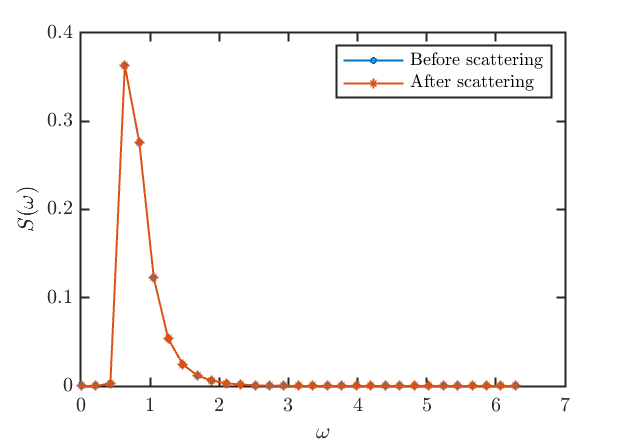






conFigure(11)
f = figure;
plot(omega,S_attn(scatter_loc,:),'o-')
hold on
plot(omega,S_attn_scattering(scatter_loc,:),'*-')
%text(3,1,sprintf('Energy before = %g',sum(int_E_f_theta.*dwavew)))
%text(3,0.8,sprintf('Energy after = %g',sum(int_E_f_theta.*(1-beta_N).*dwavew)))
xlabel('$\omega$')
ylabel('$S(\omega)$')
legend('Before scattering','After scattering')
exportgraphics(f,'comp_scatter.pdf','ContentType','vector')

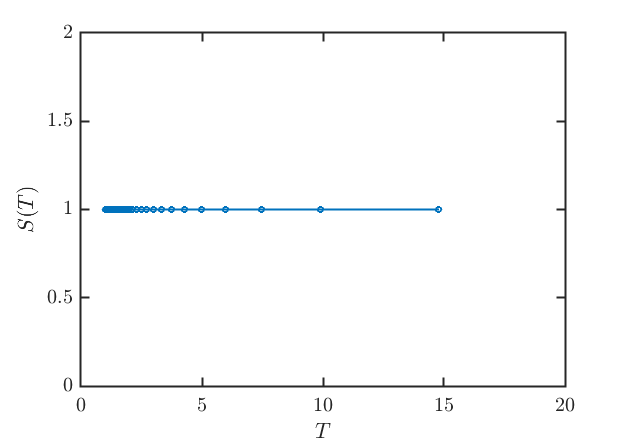



conFigure(11)
f = figure;
plot((2*pi)./omega,S_attn_scattering(scatter_loc,:)./S_attn(scatter_loc,:),'o-')

%hold on
%plot((2*pi)./omega,S_attn_scattering(scatter_pos,:),'*-')
xlabel('$T$')
ylabel('$S(T)$')
xlim([0,20])
%legend('Before scattering','After scattering')
exportgraphics(f,'comp_scatter_wavelength.pdf','ContentType','vector')

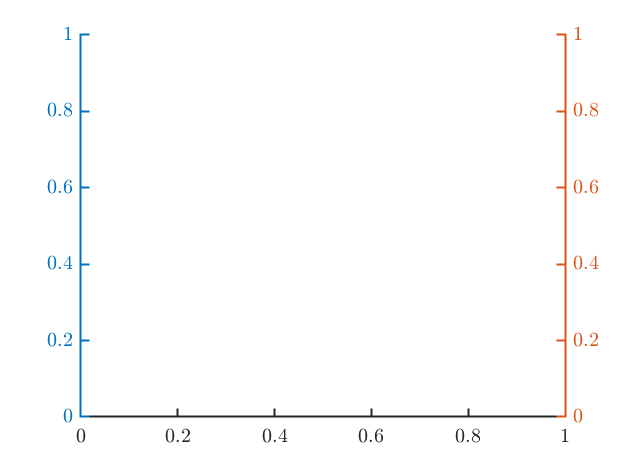



conFigure(11,1.5)
f = figure;
yyaxis left

lat_vec = -lat(cell_lon_idx,lat_range);
lat_vec(48) = lat_vec(47);
Hs(48) = round(Hs_init,2);
plot(lat_vec,Hs,'o-')

Error using plot
Vectors must be the same length.

%hold on
%plot(-lat(cell_lon_idx,47),round(Hs_init,2),'o')
%hold on
%plot(-lat(cell_lon_idx,lat_range),Hs,'o')
%plot(-lat(cell_lon_idx,lat_range),Hs_scattering,'^')
xa = [0.3,0.3]; %[-lat(cell_lon_idx,lat_range(end)-1) -lat(cell_lon_idx,lat_range(end)-1)];
ya = [0.55,0.68]; %[Hs(3) Hs_nospread(3)];
ylim([0,8])
ylabel('Signficant wave height [m]')
yyaxis right
plot(-lat(cell_lon_idx,wave_lat:-1:wave_lat-length_transect+1),aice_data(cell_lon_idx,wave_lat:-1:wave_lat-length_transect+1),'-','LineWidth',1)
pos = find(aice_data(cell_lon_idx,:) > 0.1);
ylabel('Sea ice concentration [-]')
hold off
xlabel('Latitude [$^\circ$ S]')
exportgraphics(f,'1dprop_noscat.pdf','ContentType','vector')


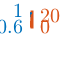

gravity = 9.80665;


for i = 1:360
    wave_locs = find(Hs_scattering(i,:)>0);
    wave_loc(i) = wave_locs(end)-scatter_loc_vec(i);
    Hs_scat_vec(i) = Hs_scattering(i,wave_loc(i));
    Hs_vec(i) = Hs(i,wave_loc(i));
    fsdrad_vec(i) = fsdrad_data(i,wave_loc(i));
    swh_lon_vec(i) = swh_data(i,wave_loc(i)+2);
    ppd_lon_vec(i) = ppd_data(i,wave_loc(i)+2);
    lambda_vec(i) = (gravity*(ppd_lon_vec(i).^2))/(2*pi);
end


conFigure(11,2)
f = figure;
yyaxis left
plot(lon(1:360,1),Hs_scat_vec./Hs_vec)
ylabel('$H_s^{Scatter}/H_s^{0}$ [-]') % 
%ylim([0.5,1])
yyaxis right
plot(lon(1:360,1),fsdrad_vec)
plot(lon(1:360,1),(2*fsdrad_vec)./lambda_vec)

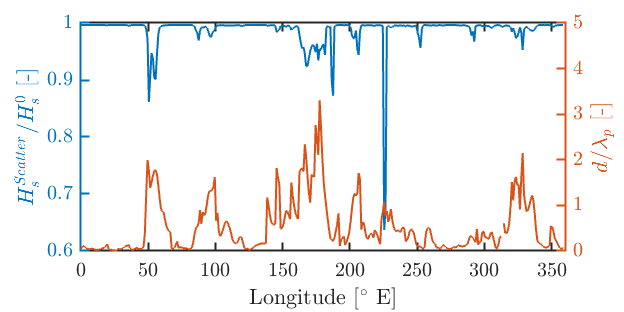

ylabel('$d/\lambda_p$ [-]')
ylim([0,5])
%ylabel('Representative floe size [m]')
xlim([0,360])
xlabel('Longitude [$^\circ$ E]')
exportgraphics(f,'hs_vs_fsdrad.pdf','ContentType','vector')

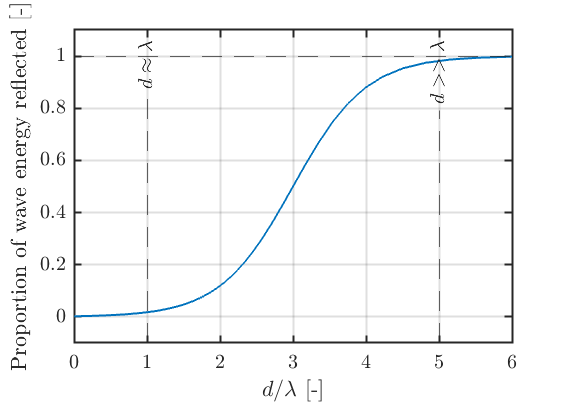

% Calculate the wavelength using the deep water surface gravity wave dispersion relation wavelength
% lambda = gT^2/(2pi)
max_ppd = 20; % Maximum ppd for swell waves is about 20s in CAWCR
min_ppd = 0.1; % Minimum ppd for swell waves is about 20s in CAWCR
Tp = linspace(min_ppd,max_ppd,1000);
gravity = 9.80665;
lambda_p = (gravity*(Tp.^2))/(2*pi);


% Scattering calculation

% Parameters
max_energy_loss = 1.0;
min_energy_loss = 0;
unity = 1;
d_gt_lambda = 5;


clear beta_N legend_names
count = 1;
NFSD = ncread(filename,"NFSD");
floe_sizes= round(NFSD,2);%[5,20,50,100]; %;[30,10,5]%5:5:30;
clear d_lambda
for n = 1:length(floe_sizes)
    floe_size = floe_sizes(n); % Diameter, m
    d_lambda(n,:) = floe_size./lambda_p;
    beta_N(n,:) = (max_energy_loss/2)*(tanh(d_lambda(n,:)-(d_gt_lambda+unity)/2)+1);
end



conFigure(10)
f = figure;
plot(d_lambda(1,:),beta_N(1,:))
hold on
legend_names(1) = sprintf("$d = $%g",floe_sizes(1));

yline(max_energy_loss,'--')
%yline(min_energy_loss,'--')
xline(unity,'--',{'$d \approx \lambda$'},'Interpreter','latex','LabelHorizontalAlignment','center')
xline(d_gt_lambda,'--',{'$d >> \lambda$'},'Interpreter','latex','LabelHorizontalAlignment','center')
grid on
xlabel('$d/\lambda$ [-]')
xlim([0,6])
ylim([-0.1,1.1])
%legend([legend_names,'',''])
ylabel('Proportion of wave energy reflected [-]')


exportgraphics(f,'beta_N.pdf','ContentType','vector')




conFigure(10)
f = figure;
for n = 1:length(floe_sizes)
    plot(lambda_p,beta_N(n,:))
    hold on
    legend_names(n) = sprintf("$d = $%g",floe_sizes(n));
end

grid on
xlabel('$\lambda$ [m]')
%xlim([min(lambda_,6])
ylim([-0.1,1.1])
legend([legend_names,'',''],'Location','eastoutside')

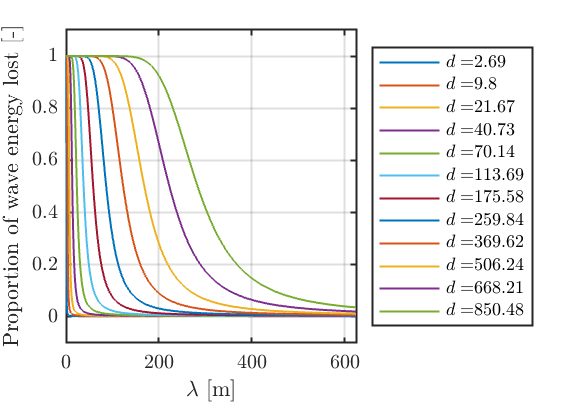

ylabel('Proportion of wave energy lost [-]')


exportgraphics(f,'lambda.pdf','ContentType','vector')



Tp = linspace(min_ppd,max_ppd,10);
gravity = 9.80665;
lambda_p = (gravity*(Tp.^2))/(2*pi);

clear beta_N legend_names
count = 1;
floe_sizes= round(NFSD,2)';%[5,20,50,100]; %;[30,10,5]%5:5:30;
clear d_lambda
for n = 1:length(lambda_p)
    lambda = lambda_p(n); % Diameter, m
    d_lambda(n,:) = floe_sizes./lambda;
    beta_N(n,:) = (max_energy_loss/2)*(tanh(d_lambda(n,:)-(5+0)/2)+1);
end

conFigure(10)
f = figure;
for n = 1:length(lambda_p)
    plot(floe_sizes,beta_N(n,:))
    hold on
    legend_names(n) = sprintf("$lambda = $%g",lambda_p(n));
end

grid on
xlabel('$d$ [m]')
%xlim([min(lambda_,6])
ylim([-0.1,1.1])
legend([legend_names,'',''],'Location','eastoutside','Interpreter','latex')

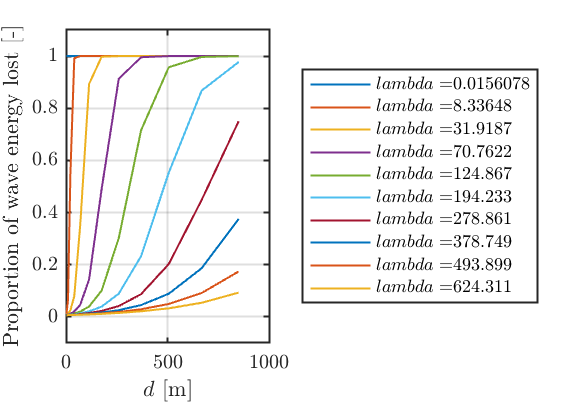

ylabel('Proportion of wave energy lost [-]')


exportgraphics(f,'d.pdf','ContentType','vector')

% Representative floe size for waves
aice = 0.9;
floe_size_data = [90 1 0.9 0.4 0.3 0.1 0.01 0.005 0.003 0.001 0.0006 5];
floe_size_data = floe_size_data./sum(floe_size_data);
floe_size_data = floe_size_data.*aice;

NCAT = ncread(filename,"NCAT");
NFSD = ncread(filename,"NFSD");
Nf = numel(NFSD);
Nc = numel(NCAT);

[floe_binwidth, floe_rad_l, floe_rad_h] = cice_parameters(NFSD);

E_r = floe_size_data*NFSD; % Mean = Expectation of F(r)
E_r2 = (1/aice)*floe_size_data*((NFSD-E_r).^2); % Variance = Second moment of F(r)
sigma2_r = (1/aice)*floe_size_data*((NFSD-E_r).^2);
median_r = NFSD(find(abs(cumsum(floe_size_data)-0.5) == min(abs(cumsum(floe_size_data)-0.5))));
mode_r = NFSD(find(floe_size_data == max(floe_size_data)));


r_a = (1/aice)*(floe_size_data*NFSD);

% r_w, representative radius for incoming waves
% See if floes in the largest floe size category are dominant, else,
% calculate the mean from the distribution ignoring that class
%r_w = (1/aice)*(floe_size_data*(NFSD.^2));

if max(floe_size_data) == floe_size_data(end)
    r_w = (1/aice)*(floe_size_data*NFSD);
else
    floe_size_data_adjusted = floe_size_data(1:end-1)./sum(floe_size_data(1:end-1)); % normalise
    r_w = (1/aice)*(floe_size_data_adjusted*NFSD(1:end-1));

    floe_size_data_adjusted = floe_size_data(2:end-1)./sum(floe_size_data(2:end-1)); % normalise
    r_w2 = (1/aice)*(floe_size_data_adjusted*NFSD(2:end-1));
end


[r_w3] = get_rep_radius_waves(floe_size_data, NFSD, aice)

r_w3 = 1×11 single row vector
1.0e+03 *

    2.4140    0.0268    0.0241    0.0107    0.0080    0.0027    0.0003    0.0001    0.0001    0.0000    0.0000


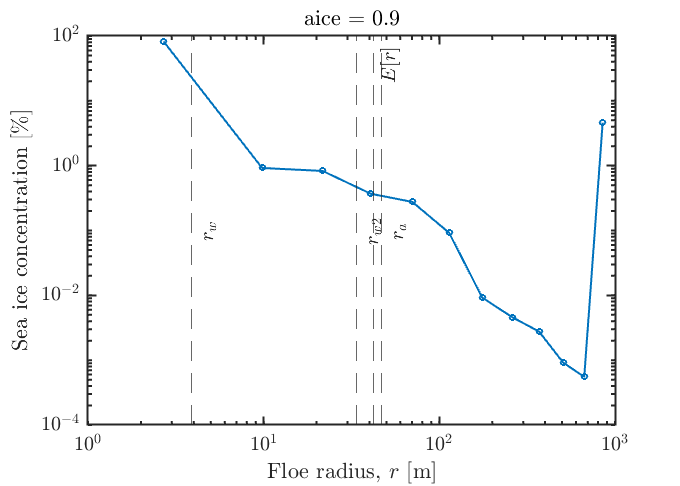



conFigure(12)
f = figure;
loglog(NFSD', floe_size_data*100,'-o')
xlabel('Floe radius, $r$ [m]')
ylabel('Sea ice concentration [\%]')

xline(E_r,'--',{'$E[r]$'},'Interpreter','latex')
%xline(median_r,'--',{'Median$(r)$'},'Interpreter','latex')
%xline(mode_r,'--',{'Mode$(r)$'},'Interpreter','latex','LabelVerticalAlignment','middle')
xline(r_a,'--',{'$r_a$'},'Interpreter','latex','LabelVerticalAlignment','middle')
xline(r_w,'--',{'$r_w$'},'Interpreter','latex','LabelVerticalAlignment','middle')
xline(r_w2,'--',{'$r_{w2}$'},'Interpreter','latex','LabelVerticalAlignment','middle')
%xline(sigma_r,'--',{'$\sigma_r$'},'Interpreter','latex')
%xline(E_r2,'--',{'$E[r^2]$'},'Interpreter','latex')
%xline(E_r2/(sigma_r),'--',{'$E[r^2]/\sigma^2$'},'Interpreter','latex')


title(sprintf('aice = %g',aice))

exportgraphics(f,'loglogfsd.pdf','ContentType','vector')

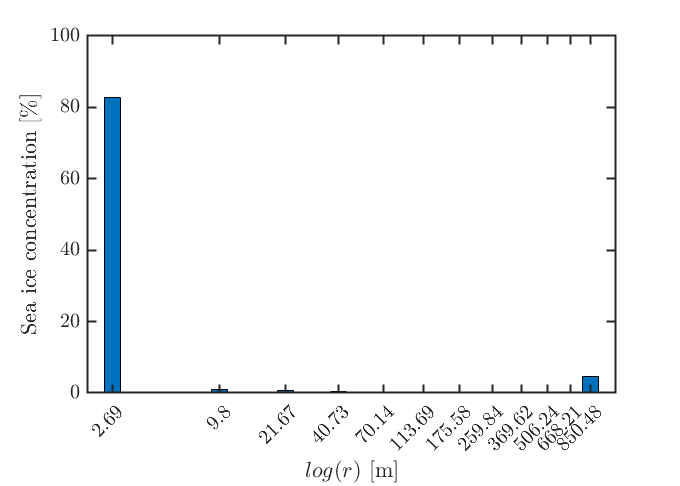


f = figure;
bar(log(NFSD), floe_size_data*100)
xlabel('$log(r)$ [m]')
xticks(log(NFSD))
xticklabels(num2str(round(NFSD,2)))
ylabel('Sea ice concentration [\%]')
exportgraphics(f,'barfsd.pdf','ContentType','vector')

% Plot a map of r_w

afsd_data = data_format(filename,'afsd');

[len,wid] = size(aice_data);

for i = 1:len
    for j = 1:wid
        if aice_data(i,j) > 0.01
            rw_map(i,j) = get_rep_radius_waves(squeeze(afsd_data(i,j,:))./floe_binwidth', NFSD, aice_data(i,j));
        else
            rw_map(i,j) = NaN;
        end
    end
end

conFigure(11,1)
f = figure;
w = worldmap('world');
    axesm eqaazim; %, eqaazim wetch eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-50]);
    setm(w, 'maplonlimit', [-180,180]);

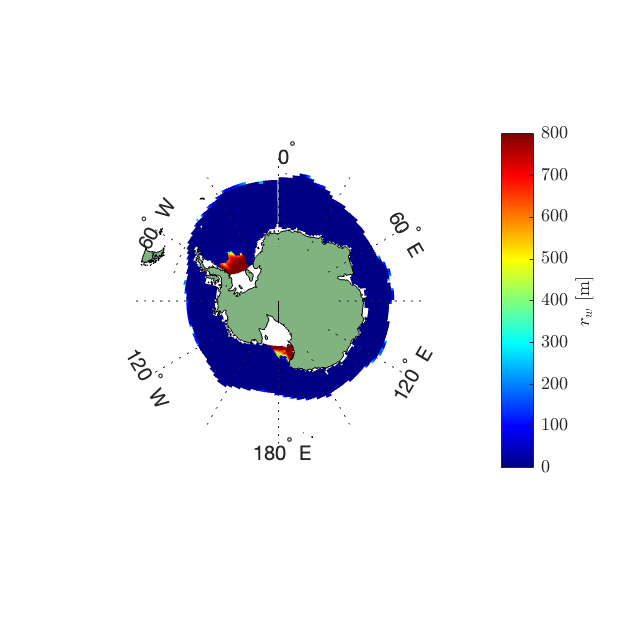

    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', 60);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'mlinelimit', [-75 -50]);
    setm(w, 'plinelimit', [-75 -50]);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'off');
    setm(w, 'labelrotation', 'on')
    pcolorm(double(lat),double(lon),rw_map) 
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    a = colorbar;
    a.Label.String = "$r_w$ [m]";
    a.TickLabelInterpreter = 'latex';
    a.Label.Interpreter = 'latex';
    caxis([0,800])
    colormap('jet')
    
exportgraphics(f,'rw_map.pdf','ContentType','vector')


fsdrad_data = data_format(filename,'fsdrad');

conFigure(11,1)
f = figure;
w = worldmap('world');
    axesm eqaazim; %, eqaazim wetch eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-50]);
    setm(w, 'maplonlimit', [-180,180]);

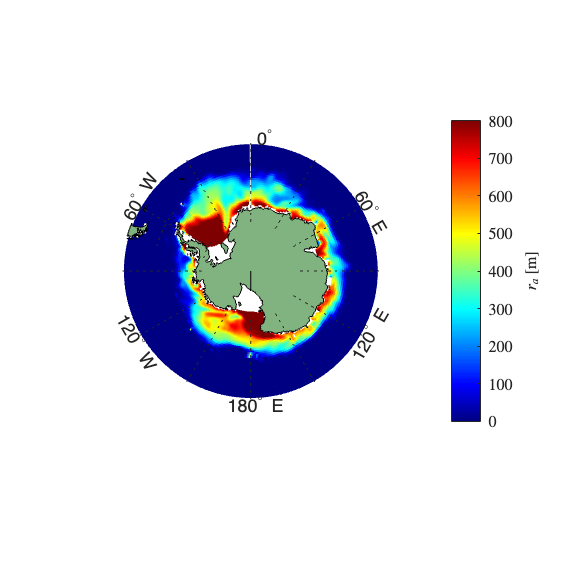

    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', 60);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', -45);
    setm(w, 'mlinelimit', [-75 -50]);
    setm(w, 'plinelimit', [-75 -50]);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'off');
    setm(w, 'labelrotation', 'on')
    pcolorm(double(lat),double(lon),fsdrad_data) 
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    a = colorbar;
    a.Label.String = "$r_a$ [m]";
    a.TickLabelInterpreter = 'latex';
    a.Label.Interpreter = 'latex';
    %caxis([0,10])
     caxis([0,800])
    colormap('jet')
    
exportgraphics(f,'ra_map.pdf','ContentType','vector')

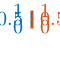



conFigure(11,2)
f= figure;
yyaxis left

plot(-transect.tlat(wave_lat:-1:wave_lat-length_transect+1),Hs)

Unable to resolve the name 'transect.tlat'.

xlim([50,70])

yyaxis right
plot(-transect.tlat,aice_test)
hold off
legend('SWH','Ice concentration','Location','northeast')



figure
yyaxis left
plot(-lat_vec, swh_data_vec)
ylabel('Significant wave height [m]')
yyaxis right 
plot(-lat_vec, aice_data_vec)
ylabel('Areal ice concentration [-]')
xlabel('Latitude [$^\circ$ S]')

fsdrad_data = data_format_sector(filename,"fsdrad",sector);
fsdrad_data_vec= fsdrad_data(lon_pos,lat_range);

figure
yyaxis left
plot(-lat_vec, swh_data_vec)
ylabel('Significant wave height [m]')
yyaxis right 
plot(-lat_vec, fsdrad_data_vec)
ylabel('Mean floe size [m]')
xlabel('Latitude [$^\circ$ S]')

% Plot the map of the propagated waves through ice 

% CIRCUMPOLAR propagation










% JUNK CODE


land_mask = isnan(aice_data(cell_lon_idx,:));
aice_test = zeros(size(aice_data(cell_lon_idx,:)));
aice_test(land_mask) = NaN;

for i = 2:length_transect
    conc = aice_test(wave_lat-i+1); %aice_data(cell_lon_idx,wave_lat-i+1);

n_vec =     1.0000    2.5000    5.0000


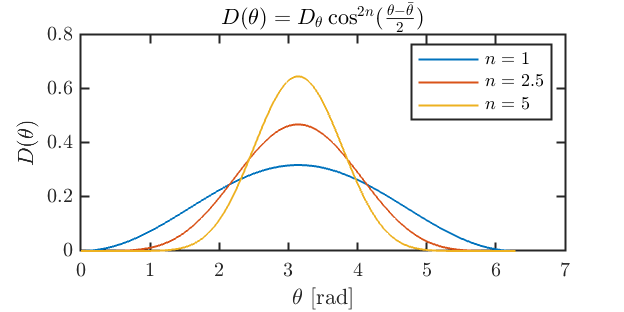

    hice = hice_data(cell_lon_idx,wave_lat-i+1);
    if isnan(conc) % Land
        S_attn(i,:) = zeros(1,nw);
    else
        if conc > tolice && hice > thice
            for j = 1:16
                attn_spec(i,j) = fn_Attn_MBK(omega(j));
                alpha(i,j) = conc*attn_spec(i,j)/0.7;
                exp_term(i,j) = exp(-alpha(i,j)*L(i));
                S_attn(i,j) = S_attn(i-1,j).*exp_term(i,j);
            end
        else
            S_attn(i,:) = S_attn(i-1,:);
        end
    end
end

%sub_Uncoupled


fn_Attn_MBK(omega(1))

for i = 1:length_transect
    Hs(i) = 4*sqrt(sum(S_attn(i,:).*dwavefreq)); % sig wave height

end


addpath /Users/noahday/GitHub/CICE-plotting-tools/functions

Error using internal.matlab.imagesci.nc/openToRead
Could not open
/Volumes/NoahDay5TB/WIMonAlessandroRun/history/iceh.2017-07-01.nc
for reading.

Error in internal.matlab.imagesci.nc (line 124)
                    this.openToRead();

Error in ncinfo (

thn = 301;
mwd = pi;
theta_vec = linspace(mwd-pi,mwd+pi,thn);
theta0 = pi;
n_vec = [1,2.5,5]
clear D int_D
count = 1;
for i = 1:length(n_vec)
    n = n_vec(i);
    %D(count,:) = cos((theta_vec-theta0)/2).^(2*n);
    % Integration step
    %low_bnd = theta0 - pi/2 < theta_vec;
    %upp_bnd = theta_vec < theta0 + pi/2;
    %bnd = low_bnd.*upp_bnd;
    %D(count,~bnd) = 0;
    %dtheta = theta_vec(1:end) - [0,theta_vec(1:end-1)];
    %int_D = sum(D(count,:).*dtheta)
    %D(count,:) = D(count,:)./int_D;
    theta_m = theta0;
    [~,D(i,:),theta_vec] = cosine_spreader(S_init,theta_m,thn,n);
end
conFigure(11,2)
f = figure;
plot(theta_vec,D)
legend(sprintf('$n =$ %g',n_vec(1)), sprintf('$n =$ %g',n_vec(2)), sprintf('$n =$ %g',n_vec(3)))

muhat = 0.0833

muci =     0.0508
    0.1613


ylabel('$D(\theta)$')
xlabel('$\theta$ [rad]')
title('$D(\theta) = D_{\theta}\cos^{2n}(\frac{\theta-\bar{\theta}}{2})$')
exportgraphics(f,'dirspread_n.pdf','ContentType','vector')




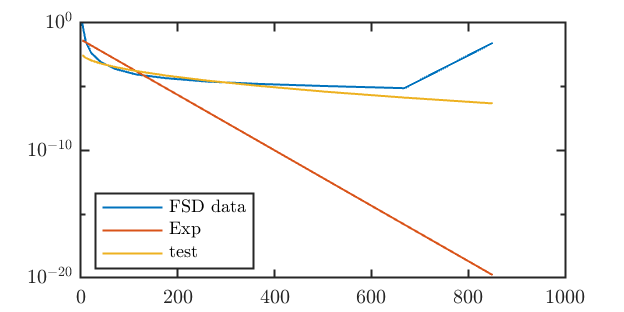

% FSD log-normal fit? or exponential
afsd_data = data_format(filename,"afsd");
NCAT = ncread(filename,"NCAT");
NFSD = ncread(filename,"NFSD");

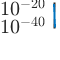

Nf = numel(NFSD);
Nc = numel(NCAT);

[floe_binwidth, floe_rad_l, floe_rad_h] = cice_parameters(NFSD);

fsd = [];
[len, wid, ~] = size(afsd_data);

for i = 1:len
    for j = 1:wid
        if aice_data(i,j) > 0.15
            clear fsd_temp
            fsd_temp = squeeze(afsd_data(i,j,:))./aice_data(i,j);
            fsd = [fsd; fsd_temp];
        end
    end
end



ave_fsd = mean(fsd(~isnan(fsd(:,1)),:));
ave_fsd = ave_fsd./sum(ave_fsd);
pd = fitdist(ave_fsd','exponential');
[muhat,muci] = expfit(ave_fsd') % Distribution specific function
x = NFSD;%linspace(min(NFSD),max(NFSD),12);
fit_pdf = exppdf(x,20);
fx = 0.005*exp(-(0.1*x).^(0.5));
f = figure;
plot(NFSD,ave_fsd)
hold on
plot(x,fit_pdf)
plot(x,fx)
legend('FSD data','Exp','test','Location','southwest')
set(gca, 'YScale', 'log')
exportgraphics(f,'fsdplot.pdf','ContentType','vector')

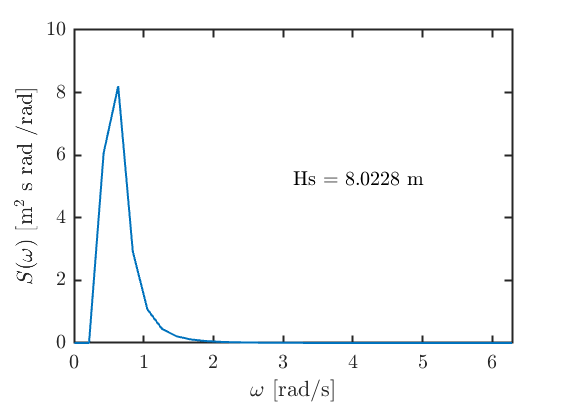


x = linspace(min(NFSD),max(NFSD),1000);
fit_pdf = exppdf(x,muhat);
figure
plot(x,fit_pdf)
set(gca, 'YScale', 'log')


#### Sanity check

Converting between frequency, period and wavelength for the spectrum.

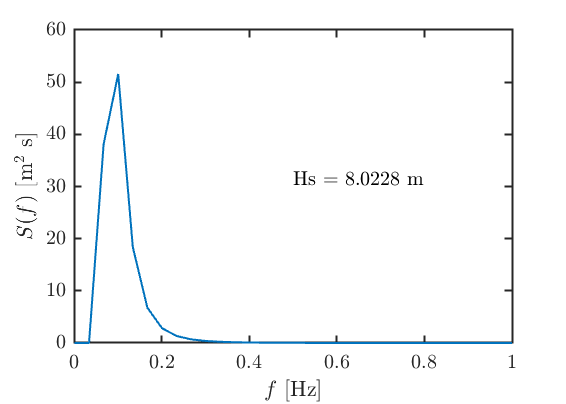

% Calculate the wavelength using the deep water surface gravity wave dispersion relation wavelength
% lambda = gT^2/(2pi)
max_ppd = 20; % Maximum ppd for swell waves is about 20s in CAWCR
min_ppd = 0.1; % Minimum ppd for swell waves is about 20s in CAWCR
Tp = linspace(min_ppd,max_ppd,1000);
gravity = 9.80665;

% Sanity check - integration of Spectra of frequency and wavelength
Hs_init = 8;
Tp_init = 12;

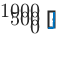

nw = 31;
[S_omega,omega,T] = SDF_Bretschneider(Hs_init,Tp_init,nw); 
domega = omega(1:end) - [0,omega(1:end-1)];

wavefreq = omega/(2*pi);%omega(end:-1:1)/(2*pi);

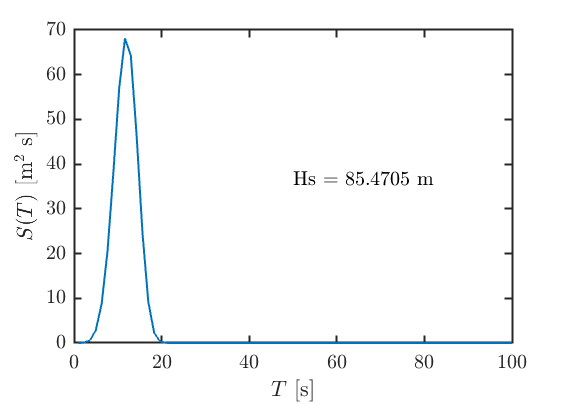

dwavefreq = wavefreq(1:end) - [0,wavefreq(1:end-1)];


lambda = (gravity*(T.^2))/(2*pi);

dim = [0.5 0.3 0.5 0.3];

f = figure;
plot(omega,S_omega)
xlabel('$\omega$ [rad/s]')
ylabel('$S(\omega)$ [m$^2$ s rad /rad]')

str = sprintf('Hs = %g m',4*sqrt(sum(S_omega.*domega)));
annotation('textbox',dim,'String',str,'FitBoxToText','on','EdgeColor',[1,1,1],'Interpreter','latex');
exportgraphics(f,'S_omega.pdf','ContentType','vector')

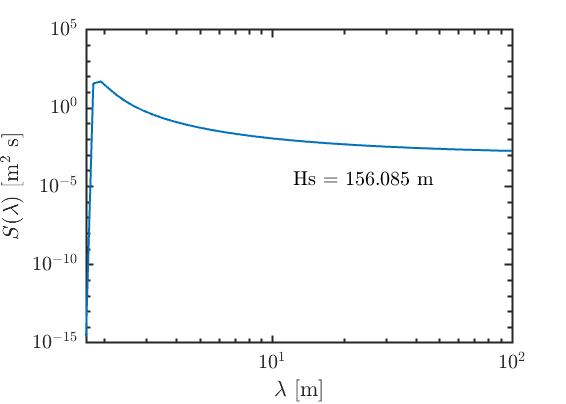


S_f = (2*pi)*S_omega;
f = figure;
plot(wavefreq,S_f)
xlabel('$f$ [Hz]')
ylabel('$S(f)$ [m$^2$ s]')
str = sprintf('Hs = %g m',4*sqrt(sum(S_f.*dwavefreq)));
annotation('textbox',dim,'String',str,'FitBoxToText','on','EdgeColor',[1,1,1],'Interpreter','latex');
exportgraphics(f,'S_freq.pdf','ContentType','vector')



f = figure;
plot(T)

[S_T,T] = SDF_BretschneiderT(Hs_init,Tp_init,301);
dT = T(1:end) - [0,T(1:end-1)]; 
f = figure;
plot(T,S_T)
xlabel('$T$ [s]')
ylabel('$S(T)$ [m$^2$ s]')
xlim([0,100])
str = sprintf('Hs = %g m',4*sqrt(sum(S_T.*dT)));
annotation('textbox',dim,'String',str,'FitBoxToText','on','EdgeColor',[1,1,1],'Interpreter','latex');
exportgraphics(f,'S_T.pdf','ContentType','vector')

S_lambda = S_f;
lambda = (gravity*(T.^2))/(2*pi);
dlambda =  lambda(1:end) - [0,lambda(1:end-1)];
f = figure;
loglog(lambda,S_lambda)
%plot(T,4*sqrt(S_T.*dT))
xlabel('$\lambda$ [m]')
ylabel('$S(\lambda)$ [m$^2$ s]')
xlim([0,10^2])
str = sprintf('Hs = %g m',4*sqrt(sum(S_lambda.*dlambda)));
annotation('textbox',dim,'String',str,'FitBoxToText','on','EdgeColor',[1,1,1],'Interpreter','latex');
exportgraphics(f,'S_lambda.pdf','ContentType','vector')

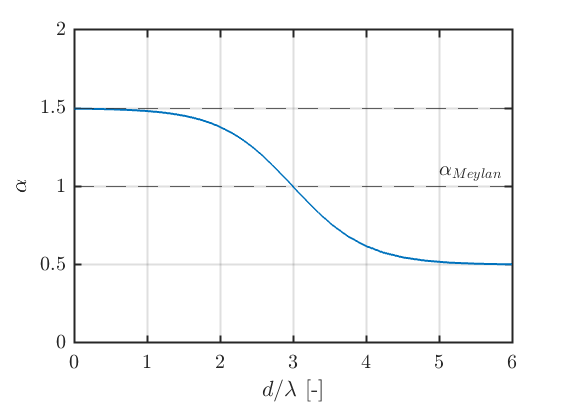



max_ppd = 20; % Maximum ppd for swell waves is about 20s in CAWCR
min_ppd = 0.1; % Minimum ppd for swell waves is about Xs in CAWCR
Tp = linspace(min_ppd,max_ppd,1000);
gravity = 9.80665;
lambda_p = (gravity*(Tp.^2))/(2*pi);
omega = 2*pi./Tp;
% Scattering calculation

% Parameters
max_alpha = 1.5;
min_alpha = 0.5;
unity = 1;
d_gt_lambda = 5;


clear beta_N legend_names
count = 1;
NFSD = ncread(filename,"NFSD");
floe_sizes= round(NFSD,2);%[5,20,50,100]; %;[30,10,5]%5:5:30;
clear d_lambda
floe_size = floe_sizes(1); % Diameter, m
d_lambda = floe_size./lambda_p;

vert_translation = (max_alpha+min_alpha)/2;
horz_translation = (d_gt_lambda+unity)/2;
amplitude = (max_alpha-min_alpha)/2;

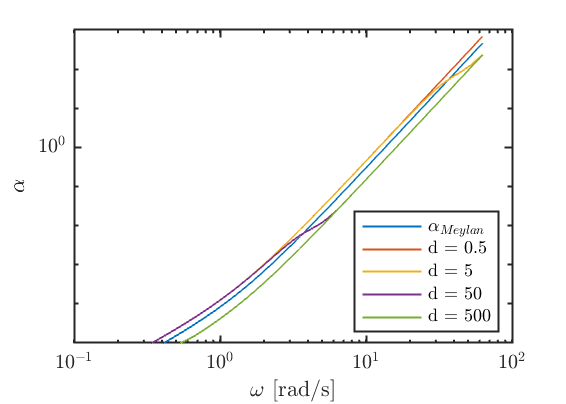

alpha_N = amplitude*tanh(-(d_lambda-horz_translation)) + vert_translation;


%attn_spec = fn_Attn_MBK(local_wave_spec)




conFigure(10)
f = figure;
plot(d_lambda(1,:),alpha_N(1,:))
hold on
legend_names(1) = sprintf("$d = $%g",floe_sizes(1));
yline(max_alpha,'--')
yline(1,'--',{'$\alpha_{Meylan}$'},'Interpreter','latex','LabelHorizontalAlignment','right')
%yline(min_energy_loss,'--')
%xline(unity,'--',{'$d \approx \lambda$'},'Interpreter','latex','LabelHorizontalAlignment','center')
%xline(d_gt_lambda,'--',{'$d >> \lambda$'},'Interpreter','latex','LabelHorizontalAlignment','center')
grid on
xlabel('$d/\lambda$ [-]')
xlim([0,6])
%ylim([-0.1,2.1])
%legend([legend_names,'',''])
ylabel('$\alpha$')
ylim([0,2])
exportgraphics(f,'alpha_N.pdf','ContentType','vector')

floe_sizes = [0.5, 5, 50, 500];
for i = 1:length(floe_sizes)
    floe_size = floe_sizes(i); % Diameter, m
    dum_om = omega;

    beta0 = 5.376168295200780e-005;
    beta1 = 2.947870279251530e-005;
    
    alpha_M = beta0*(dum_om.^2) + beta1*(dum_om.^4);
    lambda = (2*pi*gravity)./omega;
    d_lambda = floe_size./lambda;
    %alpha_N(i,:) = ((max_alpha-min_alpha)/2)*(tanh(-(d_lambda-(d_gt_lambda+unity)/2))+1+min_alpha).*alpha_M(end:-1:1);
    alpha_N(i,:) = amplitude*tanh(-(d_lambda-horz_translation)) + vert_translation;
    alpha_N_M(i,:) = alpha_N(i,:).*alpha_M;


end


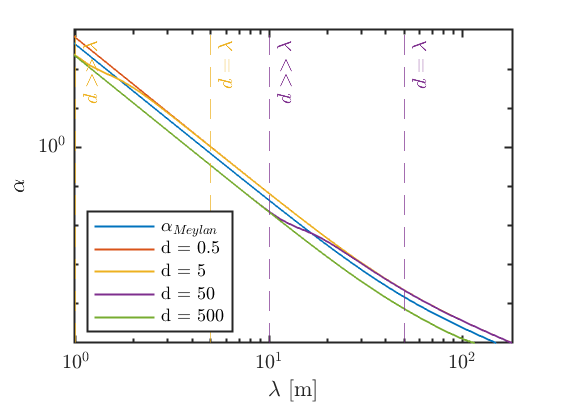


f = figure;

loglog(omega,alpha_M)
ylim([0.00001,1000])
hold on

loglog(omega,alpha_N_M)
set(gca, 'YScale', 'log')
xlabel('$\omega$ [rad/s]')
ylabel('$\alpha$')
legend('$\alpha_{Meylan}$','d = 0.5','d = 5','d = 50','d = 500','Location','southeast')
exportgraphics(f,'alpha_comp.pdf','ContentType','vector')

f = figure;
loglog(lambda,alpha_M)
ylim([0.00001,1000])
hold on
loglog(lambda,alpha_N_M(:,:))
xlabel('$\lambda$ [m]')
ylabel('$\alpha$')

%xline(floe_sizes(1),'--',{'$d = \lambda$'},'Interpreter','latex','LabelHorizontalAlignment','right','color',[0.8500 0.3250 0.0980])
xline(floe_sizes(2),'--',{'$d = \lambda$'},'Interpreter','latex','LabelHorizontalAlignment','right','color',[0.9290 0.6940 0.1250])
xline(floe_sizes(3),'--',{'$d = \lambda$'},'Interpreter','latex','LabelHorizontalAlignment','right','color',[0.4940 0.1840 0.5560])
%xline(floe_sizes(4),'--',{'$d = \lambda$'},'Interpreter','latex','LabelHorizontalAlignment','right','color',[0.4660 0.6740 0.1880])
%xline(floe_sizes(1)./5,'--',{'$d >> \lambda$'},'Interpreter','latex','LabelHorizontalAlignment','right','color',[0.8500 0.3250 0.0980])
xline(floe_sizes(2)./5,'--',{'$d >> \lambda$'},'Interpreter','latex','LabelHorizontalAlignment','right','color',[0.9290 0.6940 0.1250])
xline(floe_sizes(3)./5,'--',{'$d >> \lambda$'},'Interpreter','latex','LabelHorizontalAlignment','right','color',[0.4940 0.1840 0.5560])
%xline(floe_sizes(4)./5,'--',{'$d >> \lambda$'},'Interpreter','latex','LabelHorizontalAlignment','right','color',[0.4660 0.6740 0.1880])
legend('$\alpha_{Meylan}$','d = 0.5','d = 5','d = 50','d = 500','','','','','Location','southwest')
exportgraphics(f,'alpha_comp_lambda.pdf','ContentType','vector')

%function attn_spec = fn_Attn_MBK(local_wave_spec)
%    % Attenuate according to Meylan et al. (2014)
%    dum_om = local_wave_spec;
%    attn_fac = 1;
%    beta0 = 5.376168295200780e-005;
%    beta1 = 2.947870279251530e-005;
%    
%    fn_Attn_MBK1 = beta0*(dum_om.^2) + beta1*(dum_om.^4);
%    
%    attn_spec = attn_fac*fn_Attn_MBK1;
%end



## FUNCTIONS

function [S,omega,T] = SDF_Bretschneider(Hs,Tm,nw)
    fmin = 1/1000;%1/50;%1/16; % freq min
    fmax = 1;%1/2;%1/6; % freq max
    om1=2*pi*fmin; % ang freqs, rad/s
    om2=2*pi*fmax;
    om_0 = (om2 - om1)/(nw-1); % steps
    gravit = 9.81;
    % Calculate wave numbers and wavelengths
    for lp_i=1:nw
      omega(lp_i)        = om1 + (lp_i-1)*om_0; % Frequency, rad/s
      T(lp_i)            = 2*pi/omega(lp_i); % Period, s
      lam_wtr_in(lp_i)   = gravit*(T(lp_i)^2)/2/pi; % Wave number
      k_wtr_in(lp_i)     = 2*pi/lam_wtr_in(lp_i); % Wave length
    end
    
    tmin = 1/fmax;
    tmax = 1/fmin;
    t1 = tmin;
    t2 = tmax;
    t_0 = (t2-t1)/(nw-1);
    
    
    %clear omega
    % Define steps in terms of period not frequency
    %for lp_i=1:nw
    %   T(lp_i) = t1 + (lp_i-1)*t_0;
    %   omega(lp_i) = 2*pi/T(lp_i);
    %end


    %  omega(lp_i)        = om1 + (lp_i-1)*om_0; % Frequency, rad/s
    %  T(lp_i)            = 2*pi/omega(lp_i); % Period, s
    %  lam_wtr_in(lp_i)   = gravit*(T(lp_i)^2)/2/pi; % Wave number
    %  k_wtr_in(lp_i)     = 2*pi/lam_wtr_in(lp_i); % Wave length
    %end
    



    
    for lp_i = 1:nw
        om_m = 2*pi/Tm; % Peak angular frequency, rad/s
        tau(lp_i)  = 2*pi/omega(lp_i); % s
    end
    
    moment_no = 0;
    f1 = (5/16)*(Hs.^2)*(om_m.^4); % m^2/s^4
    f2 = omega.^(moment_no-5); % rad/s^-5
    f3 = exp(-1.25*((tau/Tm).^4)); % dimensionless (as exponentials have no dimension)

    S = f1.*f2.*f3; % rad x m^2 s/rad
end


function [S,T] = SDF_BretschneiderT(Hs,Tm,nw)
    fmin = 1/400;%1/50;%1/16; % freq min
    fmax = 1;%1/2;%1/6; % freq max

    Tmin = 1/fmax; % s
    Tmax = 1/fmin; % s

    T1=Tmin; % ang freqs, rad/s
    T2=Tmax;
    T_0 = (T2 - T1)/(nw-1); % steps
    gravit = 9.81;
    % Calculate wave numbers and wavelengths
    for lp_i=1:nw
      T(lp_i)        =  T1 + (lp_i-1)*T_0; % Period, s
      %lam_wtr_in(lp_i)   = gravit*(T(lp_i)^2)/2/pi; % Wave length
      %k_wtr_in(lp_i)     = 2*pi/lam_wtr_in(lp_i); % Wave number
    end
    
%    tmin = 1/fmax;
%    tmax = 1/fmin;
%    t1 = tmin;
%    t2 = tmax;
%    t_0 = (t2-t1)/(nw-1);
    
%    for lp_i = 1:nw
%        om_m = 2*pi/Tm; % Peak angular frequency, rad/s
%        tau(lp_i)  = 2*pi/omega(lp_i); % s
%    end
    
    moment_no = 0;
    f1 = (5/16)*(Hs.^2)*(Tm.^(-4)); % m^2/s^4
    f2 = T.^(5); % rad/s^-5
    f3 = exp(-1.25*((T./Tm).^4)); % dimensionless (as exponentials have no dimension)
    S = f1.*f2.*f3; % rad x m^2 s/rad
end

function attn_spec = fn_Attn_MBK(local_wave_spec)
    % Attenuate according to Meylan et al. (2014)
    dum_om = local_wave_spec;
    beta0 = 5.376168295200780e-005;
    beta1 = 2.947870279251530e-005;
    
    fn_Attn_MBK1 = beta0*(dum_om.^2) + beta1*(dum_om.^4);
    attn_fac = 1;
    attn_spec = attn_fac*fn_Attn_MBK1;
end


function attn_spec = fn_Attn_MBKT(dum_T)
    % Attenuate according to Meylan et al. (2014)
    attn_fac = 1;
    a = 2.12e-3; % s^2/m
    b = 4.59e-2; % s^4/m
    
    fn_Attn_MBK2 = a*(dum_T.^(-2)) + b*(dum_T^(-4));
    
    attn_spec = attn_fac*fn_Attn_MBK2;
end

function [int_E_f_theta,D,theta_vec] = cosine_spreader(S_init,theta_m,thn,n)
    % Spread the wave spectrum through angular space
    % theta 
    % theta_m is the mean wave direction [rad], South = 0
    % and integrate over -pi/2 to pi/2
    % theta0 is the MWD
    % D is the energy in directional spectrum
    % theta_vec is the corresponding angles for D
    % n is the index

    theta_vec = linspace(theta_m-pi,theta_m+pi,thn);
    low_bnd = theta_m - pi < theta_vec;
    upp_bnd = theta_vec < theta_m + pi;
    bnd = low_bnd.*upp_bnd;
    D = zeros(1,thn);
    D = cos((theta_vec-theta_m)/2).^(2*n);
    D(~bnd) = 0; % Limiting the widths of the cosine in [theta_m - pi/2, theta0 + pi/2] 

    dtheta = theta_vec(1:end) - [0,theta_vec(1:end-1)];
    C = 1/sum(D.*dtheta); % Normalising constant
    D = C*D; % Normalising the directional spectrum

    %D = (2/pi).*(cos(theta_vec-theta0)).^n;
    %
    % Integration step
    %upper = pi/2;
    %lower = 3*pi/2;
    %low_bnd = lower < theta_vec;
    %upp_bnd = theta_vec < upper; 
    %%bnd = low_bnd | upp_bnd;
    %D(~bnd) = 0;
    %dtheta = theta_vec(1:end) - [0,theta_vec(1:end-1)];
    %int_D = sum(D.*dtheta);
    
    % Integration step
%    low_bnd = theta0 - pi/2 < theta_vec;
%    upp_bnd = theta_vec < theta0 + pi/2;
%    bnd = low_bnd.*upp_bnd;
%    D(~bnd) = 0;
%    dtheta = theta_vec(1:end) - [0,theta_vec(1:end-1)];
%    int_D = sum(D.*dtheta);
%    D = D./int_D;

    % Integrate over the Southern wedge
    lower = -pi/2;
    upper = pi/2;
    low_bnd = lower < theta_vec;
    upp_bnd = theta_vec < upper;
    bnd = low_bnd & upp_bnd;
    lower = 3*pi/2;
    upper = pi/2;
    low_bnd = lower < theta_vec;
    upp_bnd = theta_vec < upper;
    bnd2 = low_bnd | upp_bnd;
    bnd = bnd | bnd2;
    E_f_theta = S_init'*D;
    int_E_f_theta = sum(S_init'*(dtheta(bnd).*D(bnd)),2)';

end

function [data_out] = data_format_cawcr(filedir,variable)
    % OM2 grid

    lon = ncread(filedir,'LON');
    lat = ncread(filedir,'LAT');

    row = 281;
    dim = 3;
    data1 = ncread(filedir, variable);
    
    latitude = [-90,90];
    longitude = [-180,180];
    

    data1 = rearrange_matrix(data1,row,dim);
    
    % fixing data
    [m, ~] = size(lon);
    lon = [lon; lon(end,:) + 360/m];
    lat = [lat; lat(end,:)];
    data_out = [data1; data1(end,:,:)];

end




function [S_out] = wave_attenuation(conc,L,nw,S_in,omega,option,floe_size)
% conc is aice
% L is the length of the cell [m]
% nw is the number of points in frequency space
% S_in is the incoming wave spectra
% option : integer
     % Do MBK exponential attenuation
    if option == "MBK"
    for lp_i=1:nw
      alpha(lp_i)  = conc*fn_Attn_MBK(omega(lp_i))/0.7; % 0.7 comes from the concentration measures in the observations of MBK
      S_out(lp_i) = S_in(lp_i)*exp(-alpha(lp_i)*L);
    end 
    else
        % Adjusted alpha
        gravity = 9.80665;
        T = (2*pi)./omega;
        lambda = (gravity*(T.^2))/(2*pi); % Wave lengths
    
        % Parameters
        max_alpha = 2.0;
        min_alpha = 0.5;
        unity = 1;
        d_gt_lambda = 5;

        d_lambda = 2*floe_size./lambda; % Diameter/wavelength
        vert_translation = (max_alpha+min_alpha)/2;
        horz_translation = (d_gt_lambda+unity)/2;
        amplitude = (max_alpha-min_alpha)/2;
        
        for lp_i=1:nw
            alpha_M(lp_i) = conc*fn_Attn_MBK(omega(lp_i))/0.7; % 0.7 comes from the concentration measures in the observations of MBK
            alpha_N(lp_i) = amplitude*tanh(-(d_lambda(lp_i)-horz_translation)) + vert_translation;
            alpha(lp_i)  = alpha_N(lp_i)*alpha_M(lp_i); 
            S_out(lp_i) = S_in(lp_i)*exp(-alpha(lp_i)*L);
        end 
    end
end




function [r_w] = get_rep_radius_waves(floe_size_data, NFSD, aice)
    % floe_size_data
    if max(floe_size_data) == floe_size_data(end)
        floe_size_data_adjusted = floe_size_data(2:end)./sum(floe_size_data(2:end)); % normalise
        r_w = (1/aice)*sum(floe_size_data_adjusted.*NFSD(2:end));
    else
        floe_size_data_adjusted = floe_size_data(1:end-1)./sum(floe_size_data(1:end-1)); % normalise
        r_w = (1/aice)*sum(floe_size_data_adjusted.*NFSD(1:end-1));
    end

end



function [S_out] = wave_scatter(S_in,omega,floe_size)
    % Setup
    gravity = 9.80665;
    T = (2*pi)./omega;
    lambda = (gravity*(T.^2))/(2*pi); % Wave lengths
    
    % Scattering calculation
    % Parameters
    max_energy_loss = 1.0;
    min_energy_loss = 0;
    d_gt_lambda = 5;
    unity = 1;
    amplitude = (max_energy_loss-min_energy_loss)/2;

    d_lambda = 2*floe_size./lambda; % Converting from radius to diameter
    beta_N = amplitude*(tanh(d_lambda(:)-(d_gt_lambda+unity)/2)+1)';
    S_out = S_in.*(1-beta_N);
end

